clear all
x1 = 200;
x2 = 800;
[pathsSpikes tmp] = ReadPCAPaths('D:\Jazmin\MultichannelDataTanks\Cortex\');
%Obtains the paths to all the content in the specified path

[DataTable] = ReadUnitTableMultichannel("A2",1,'D:\Jazmin\MultichannelDataTanks\Cortex\V1_tracks.xlsx');
%read the excel table and saves it in a variable

[pathsSpikesMultichannel] = pathsMultichannel(tmp,pathsSpikes,DataTable);
%It creates the path to the units inlcuded in the excel table

[BST, BST_MUA] = ExtractDataMultiChannel(DataTable,pathsSpikesMultichannel); %It gets a structure wiht all the BST

UN = load ('D:\Jazmin\MultichannelDataTanks\Cortex\spiketable_Aud_Sig_revised.mat');
MUA = load ('D:\Jazmin\MultichannelDataTanks\Cortex\spiketable_Aud_Sig_MUA_revised.mat');
% UN.spiketable.unitloc = [];
SpiketableComplete = [UN.spiketable;MUA.spiketable];
%It contains structures with all the units that have an auditory response

load('D:\Jazmin\MultichannelDataTanks\Cortex\CompleteSpikes_MUA.mat')
load('D:\Jazmin\MultichannelDataTanks\Cortex\CompleteSpikes.mat')

%Add a sweep identifier 1 to 400 for each trial
for i = 1:1:size(BST,1)
    y = 0;
    for j = 2:1:3060
        if BST(i).bst.Epocs.Values.wfrq(j-1,1) == 100 && BST(i).bst.Epocs.Values.wfrq(j,1) > 100
            BST(i).bst.Epocs.Values.swee(j:j+399,1) = [1:400]';
        end
    end
end


%These section creates a vector for each recording with the row number
%where each kind of stimulus of interest happen and saves it in a structure
for i = 1:1:size(BST,1)
    ODDTrialIndex = zeros(80,1);
    ODDTrialIndexP = zeros(80,1);
    CTR_ASCTrialIndex = zeros(160,1);
    CTRMSTrialIndex_F1 = zeros(160,1);
    STDMSTrialIndex = zeros(80,1);
    STDTrialIndex = zeros(80,1);
    AllSTDTrialIndex = zeros(360,1);
    AllSTDTrialIndexP = zeros(360,1);
    n = 1;
    m = 1;
    mn = 1;
    mm = 1;
    mp = 1;
    k = 1;
    p = 1;
    pp = 1;
    t = 1;
    tt = 1;
    q = 1;
    r = 1;
    s = 0;
    for j = 1:1:3060
        if isempty(cell2mat(BST(i).bst.Epocs.Values.type(j,1)))
            s = s + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'DEV')
            ODDtrials(n,1) = BST(i).bst.Epocs.Values.swee(j,1);
            ODDTrialIndex(n,1) = j;
            n = n + 1;
            %        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'DEV')
            %     %             ODDtrials(n,1) = BST(i).bst.Epocs.Values.swee(j,1) + 1;
            %                 ODDTrialIndexP(q,1) = j;
            %                 q = q + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-ASC-F1');
            CTR_ASC_F1trials(m,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_ASC_F1TrialIndex(m,1) = j;
            m = m + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-ASC-F2');
            CTR_ASC_F2trials(mn,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_ASC_F2TrialIndex(mn,1) = j;
            mn = mn + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-DES-F1');
            CTR_DESC_F1trials(mm,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_DESC_F1TrialIndex(mm,1) = j;
            mm = mm + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-DES-F2');
            CTR_DESC_F2trials(mp,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_DESC_F2TrialIndex(mp,1) = j;
            mp = mp + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'MS-F1');
            CTRMStrials_F1(t,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTRMSTrialIndex_F1(t,1) = j;
            t = t + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'MS-F2');
            CTRMStrials_F2(tt,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTRMSTrialIndex_F2(tt,1) = j;
            tt = tt + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'STD')
            STDtrials(k,1) = BST(i).bst.Epocs.Values.swee(j,1);
            STDTrialIndex(k,1) = j;
            k = k + 1;
        end

    end

    for iii = 21:1:1740

        % if isempty(cell2mat(BST(i).bst.Epocs.Values.type(iii,1))) && BST(i).bst.Epocs.Values.wfrq(iii,1)>100
        % 
        %     AllSTDtrials(p,1) = BST(i).bst.Epocs.Values.swee(iii,1);
        %     AllSTDTrialIndex(p,1) = iii;
        %     p = p + 1;
       if contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDR') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'')
           AllSTDtrials(p,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndex(p,1) = iii;
            p = p + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDR') | contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'STD') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'ODDR')
            AllSTDtrials(p,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndex(p,1) = iii;
            p = p + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDP') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'')
            AllSTDtrialsP(pp,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndexP(pp,1) = iii;
            pp = pp + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDP') | contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'STD') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'ODDP')
            AllSTDtrialsP(pp,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndexP(pp,1) = iii;
            pp = pp + 1;
        end
    end

    ODDTrialIndexP = [ODDTrialIndex(41:80);ODDTrialIndex(121:160)];
    ODDTrialIndex = [ODDTrialIndex(1:40);ODDTrialIndex(81:120)];
    STDTrialIndexP = [ STDTrialIndex(41:80); STDTrialIndex(121:160)];
    STDTrialIndex = [ STDTrialIndex(1:40); STDTrialIndex(81:120)];

    ODDtrialsP = [ODDtrials(41:80);ODDtrials(121:160)];
    ODDtrials = [ODDtrials(1:40);ODDtrials(81:120)];
    STDtrialsP = [ STDtrials(41:80); STDtrials(121:160)];
    STDtrials = [ STDtrials(1:40); STDtrials(81:120)];

    ODDTrialIndexS = struct('ODDTrialIndex', ODDTrialIndex);
    ODDTrialIndexPS = struct('ODDTrialIndexP', ODDTrialIndexP);
    CTR_DESC_F2TrialIndexS = struct('CTRTrialIndex', CTR_DESC_F2TrialIndex);
    CTR_DESC_F1TrialIndexS = struct('CTRTrialIndex', CTR_DESC_F1TrialIndex);
    CTR_ASC_F1TrialIndexS = struct('CTRTrialIndex', CTR_ASC_F1TrialIndex);
    CTR_ASC_F2TrialIndexS = struct('CTRTrialIndex', CTR_ASC_F2TrialIndex);
    CTRMSTrialIndexS_F1 = struct('CTRMSTrialIndex', CTRMSTrialIndex_F1);
    CTRMSTrialIndexS_F2 = struct('CTRMSTrialIndex', CTRMSTrialIndex_F2);
    STDTrialIndexS = struct('STDTrialIndex', STDTrialIndex);
    STDTrialIndexSP = struct('STDTrialIndex', STDTrialIndexP);
    AllSTDTrialIndexS = struct('AllSTDTrialIndex', AllSTDTrialIndex);
    AllSTDTrialIndexPS = struct('AllSTDTrialIndexP', AllSTDTrialIndexP);

    ODDTrialsS = struct('ODDtrials', ODDtrials);
    CTR_ASC_F1TrialsS = struct('CTRtrials', CTR_ASC_F1trials);
    CTR_ASC_F2TrialsS = struct('CTRtrials', CTR_ASC_F2trials);
    CTR_DESC_F1TrialsS = struct('CTRtrials', CTR_DESC_F1trials);
    CTR_DESC_F2TrialsS = struct('CTRtrials', CTR_DESC_F2trials);
    CTRMSTrialsS_F1 = struct('CTRMStrials', CTRMStrials_F1);
    CTRMSTrialsS_F2 = struct('CTRMStrials', CTRMStrials_F2);
    STDTrialsS = struct('STDtrials', STDtrials);
    STDTrialsSP = struct('STDtrials', STDtrialsP);
    ODDTrialsPS = struct('ODDtrialsP', ODDtrialsP);
    AllSTDTrialsS = struct('AllSTDtrials', AllSTDtrials);
    AllSTDTrialsPS = struct('AllSTDtrialPs', AllSTDtrialsP);

    ODDTrialIndexComplete(:,i) = ODDTrialIndexS;
    ODDTrialIndexCompleteP(:,i) = ODDTrialIndexPS;
    CTR_ASC_F1TrialIndexComplete(:,i) = CTR_ASC_F1TrialIndexS;
    CTR_ASC_F2TrialIndexComplete(:,i) = CTR_ASC_F2TrialIndexS;
    CTR_DESC_F1TrialIndexComplete(:,i) = CTR_DESC_F1TrialIndexS;
    CTR_DESC_F2TrialIndexComplete(:,i) = CTR_DESC_F2TrialIndexS;
    CTRMSTrialIndex_F1Complete(:,i) = CTRMSTrialIndexS_F1;
    CTRMSTrialIndex_F2Complete(:,i) = CTRMSTrialIndexS_F2;
    STDTrialIndexComplete(:,i) = STDTrialIndexS;
    STDTrialIndexComplete_P(:,i) = STDTrialIndexSP;
    AllSTDTrialIndexComplete(:,i) = AllSTDTrialIndexS;
    AllSTDTrialIndexCompleteP(:,i) = AllSTDTrialIndexPS;

    ODDTrialsComplete(:,i) = ODDTrialsS;
    ODDTrialsCompleteP(:,i) = ODDTrialsPS;
    CTR_ASC_F1TrialsComplete(:,i) = CTR_ASC_F1TrialsS;
    CTR_ASC_F2TrialsComplete(:,i) = CTR_ASC_F2TrialsS;
    CTR_DESC_F1TrialsComplete(:,i) = CTR_DESC_F1TrialsS;
    CTR_DESC_F2TrialsComplete(:,i) = CTR_DESC_F2TrialsS;
    CTRMSTrialsComplete_F1(:,i) = CTRMSTrialsS_F1;
    CTRMSTrialsComplete_F2(:,i) = CTRMSTrialsS_F2;
    STDTrialsComplete(:,i) = STDTrialsS;
    STDTrialsComplete_P(:,i) = STDTrialsSP;
    AllSTDTrialsComplete(:,i) = AllSTDTrialsS;
    AllSTDTrialsCompleteP(:,i) = AllSTDTrialsPS;
end

for ii = 1:size(BST_MUA,1)
    AllSTDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    ODDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    ODDTrialIndexCompleteP(ii).path = pathsSpikesMultichannel(ii,1);
    CTRTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    CTRMSTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialIndexComplete_P(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialIndexCompleteP(ii).path = pathsSpikesMultichannel(ii,1);

    ODDTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    ODDTrialsCompleteP(ii).path = pathsSpikesMultichannel(ii,1);
    CTRTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    CTRMSTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialsComplete_P(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialsCompleteP(ii).path = pathsSpikesMultichannel(ii,1);
end

AllSpikeTable = [CompleteSpikes;CompleteSpikes_MUA];

n=1;
for i = 1:size(AllSpikeTable,1)
    if AllSpikeTable.layer(i) == 5
        Layer5(n,:) = AllSpikeTable(i,:);
        n = n+1;
    end
end

AllSpikeTable = Layer5;

a = 1;
b = 1;
c = 1;
d = 1;
for i = 1:size(AllSpikeTable,1)
    if AllSpikeTable.Auditory(i) == 1
        AllSpikeTable_Auditory(a,:) = AllSpikeTable(i,:);
        a = a + 1;
    end
    if AllSpikeTable.AuditoryP(i) == 1
        AllSpikeTable_AuditoryP(b,:) = AllSpikeTable(i,:);
        b = b + 1;
    end
    if AllSpikeTable.Significance(i) == 1
        AllSpikeTable_Significance(c,:) = AllSpikeTable(i,:);
        c = c + 1;
    end
    if AllSpikeTable.SignificanceP(i) == 1
        AllSpikeTable_SignificanceP(d,:) = AllSpikeTable(i,:);
        d = d + 1;
    end
end

for i = 1:size(AllSpikeTable_Significance,1)
    AllSTDtrialsRest(i).STDtrials = setdiff(AllSTDTrialsComplete(1).AllSTDtrials(1:360),STDTrialsComplete(1).STDtrials(1:40));
    AllSTDtrialsRest_P(i).STDtrialsP = setdiff(AllSTDTrialsCompleteP(1).AllSTDtrialPs(1:360),STDTrialsComplete_P(1).STDtrials(1:40));
    AllCTRMSTrials=(1:400);
    MStrials = setdiff(AllCTRMSTrials',CTRMSTrialsComplete_F1(1).CTRMStrials);
    MStrialsRest(i).MStrials = setdiff(MStrials,CTRMSTrialsComplete_F2(1).CTRMStrials);
    AllCTRCASCascTrials=(1:400);
    CASCasctrials = setdiff(AllCTRCASCascTrials',CTR_ASC_F1TrialsComplete(1).CTRtrials);
    CASCasctrialsRest(i).CASCasctrials = setdiff(CASCasctrials,CTR_ASC_F2TrialsComplete(1).CTRtrials);
    AllCTRCASCdesTrials=(1:400);
    CASCdestrials = setdiff(AllCTRCASCdesTrials',CTR_DESC_F1TrialsComplete(1).CTRtrials);
    CASCdestrialsRest(i).CASCdes = setdiff(CASCdestrials,CTR_DESC_F2TrialsComplete(1).CTRtrials);
end

DEVcount = zeros(40,1);
    for j = 1:size(AllSpikeTable_Significance,1)
        for k = 1:1:40
            DEVtimesASC = table2array(AllSpikeTable_Significance.spikes{j,1}(k,3));
            for i = 1:size(DEVtimesASC{1,1},1)
                if DEVtimesASC{1,1}(i) >= 200 && DEVtimesASC{1,1}(i) <= 800
                    DEVcount(k) = DEVcount(k) + 1;
                end
            end
    
            DEVtimesDES = table2array(AllSpikeTable_Significance.spikes{j,1}(k,8));
            for i = 1:size(DEVtimesDES{1,1},1)
                if DEVtimesDES{1,1}(i) >= 200 && DEVtimesDES{1,1}(i) <= 800
                    DEVcount(k) = DEVcount(k) + 1;
                end
            end
        end
    end

STDcount = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        STDtimesASC = table2array(AllSpikeTable_Significance.spikes{j,1}(k,2));
        for i = 1:size(STDtimesASC{1,1},1)
            if STDtimesASC{1,1}(i) >= 200 && STDtimesASC{1,1}(i) <= 800
                STDcount(k) = STDcount(k) + 1;
            end
        end

        STDtimesDES = table2array(AllSpikeTable_Significance.spikes{j,1}(k,7));
        for i = 1:size(STDtimesDES{1,1},1)
            if STDtimesDES{1,1}(i) >= 200 && STDtimesDES{1,1}(i) <= 800
                STDcount(k) = STDcount(k) + 1;
            end
        end
    end
end


STDcountRest = zeros(640,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:640
        STDtimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,1));
        for i = 1:size(STDtimesRest{1,1},1)
            if STDtimesRest{1,1}(i) >= 200 && STDtimesRest{1,1}(i) <= 800
                STDcountRest(k) = STDcountRest(k) + 1;
            end
        end
    end
end
STDcountRest = STDcountRest(1:320)+STDcountRest(321:640);

DEVcount_P = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        DEVtimesASC_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,6));
        for i = 1:size(DEVtimesASC_P{1,1},1)
            if DEVtimesASC_P{1,1}(i) >= 200 && DEVtimesASC_P{1,1}(i) <= 800
                DEVcount_P(k) = DEVcount_P(k) + 1;
            end
        end

        DEVtimesDES_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,10));
        for i = 1:size(DEVtimesDES_P{1,1},1)
            if DEVtimesDES_P{1,1}(i) >= 200 && DEVtimesDES_P{1,1}(i) <= 800
                DEVcount_P(k) = DEVcount_P(k) + 1;
            end
        end
    end
end

STDcount_P = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        STDtimesASC_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,5));
        for i = 1:size(STDtimesASC_P{1,1},1)
            if STDtimesASC_P{1,1}(i) >= 200 && STDtimesASC_P{1,1}(i) <= 800
                STDcount_P(k) = STDcount_P(k) + 1;
            end
        end

        STDtimesDES_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,9));
        for i = 1:size(STDtimesDES_P{1,1},1)
            if STDtimesDES_P{1,1}(i) >= 200 && STDtimesDES_P{1,1}(i) <= 800
                STDcount_P(k) = STDcount_P(k) + 1;
            end
        end
    end
end

STDcountRest_P = zeros(640,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:640
        STDtimesRest_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,4));
        for i = 1:size(STDtimesRest_P{1,1},1)
            if STDtimesRest_P{1,1}(i) >= 200 && STDtimesRest_P{1,1}(i) <= 800
                STDcountRest_P(k) = STDcountRest_P(k) + 1;
            end
        end
    end
end
STDcountRest_P = STDcountRest_P(1:320)+STDcountRest_P(321:640);

MScount_F1 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,13));
        for i = 1:size(MStimes_F1{1,1},1)
            if MStimes_F1{1,1}(i) >= 200 && MStimes_F1{1,1}(i) <= 800
                MScount_F1(k) = MScount_F1(k) + 1;
            end
        end
    end
end

MScount_F2 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,12));
        for i = 1:size(MStimes_F2{1,1},1)
            if MStimes_F2{1,1}(i) >= 200 && MStimes_F2{1,1}(i) <= 800
                MScount_F2(k) = MScount_F2(k) + 1;
            end
        end
    end
end

MScount_rest = zeros(320,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        MStimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,11));
        for i = 1:size(MStimesRest{1,1},1)
            if MStimesRest{1,1}(i) >= 200 && MStimesRest{1,1}(i) <= 800
                MScount_rest(k) = MScount_rest(k) + 1;
            end
        end
    end
end

CASCasccount_F1 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,15));
        for i = 1:size(CASCasctimes_F1{1,1},1)
            if CASCasctimes_F1{1,1}(i) >= 200 && CASCasctimes_F1{1,1}(i) <= 800
                CASCasccount_F1(k) = CASCasccount_F1(k) + 1;
            end
        end
    end
end

CASCasccount_F2 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,16));
        for i = 1:size(CASCasctimes_F2{1,1},1)
            if CASCasctimes_F2{1,1}(i) >= 200 && CASCasctimes_F2{1,1}(i) <= 800
                CASCasccount_F2(k) = CASCasccount_F2(k) + 1;
            end
        end
    end
end

CASCasccount_rest = zeros(320,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCasctimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,14));
        for i = 1:size(CASCasctimesRest{1,1},1)
            if CASCasctimesRest{1,1}(i) >= 200 && CASCasctimesRest{1,1}(i) <= 800
                CASCasccount_rest(k) = CASCasccount_rest(k) + 1;
            end
        end
    end
end

CASCdescount_F1 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,19));
        for i = 1:size(CASCdestimes_F1{1,1},1)
            if CASCdestimes_F1{1,1}(i) >= 200 && CASCdestimes_F1{1,1}(i) <= 800
                CASCdescount_F1(k) = CASCdescount_F1(k) + 1;
            end
        end
    end
end

CASCdescount_F2 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,18));
        for i = 1:size(CASCdestimes_F2{1,1},1)
            if CASCdestimes_F2{1,1}(i) >= 200 && CASCdestimes_F2{1,1}(i) <= 800
                CASCdescount_F2(k) = CASCdescount_F2(k) + 1;
            end
        end
    end
end

CASCdescount_rest = zeros(320,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCdestimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,17));
        for i = 1:size(CASCdestimesRest{1,1},1)
            if CASCdestimesRest{1,1}(i) >= 200 && CASCdestimesRest{1,1}(i) <= 800
                CASCdescount_rest(k) = CASCdescount_rest(k) + 1;
            end
        end
    end
end

n = size(AllSpikeTable_Significance,1);
spike_counts = zeros(1,400);
for i = 1:40
spike_counts(1,ODDTrialsComplete(1).ODDtrials(i)) = DEVcount(i,1)./n;
spike_counts(1,STDTrialsComplete(1).STDtrials(i)) = STDcount(i,1)./n;
end

for j = 1:320
spike_counts(1,AllSTDtrialsRest(1).STDtrials(j)) = STDcountRest(j,1)./n;
end

spike_counts_P = zeros(1,400);
for i = 1:40
spike_counts_P(1,ODDTrialsCompleteP(1).ODDtrialsP(i)) = DEVcount_P(i,1)./n;
spike_counts_P(1,STDTrialsComplete_P(1).STDtrials(i)) = STDcount_P(i,1)./n;
end

for j = 1:320
spike_counts_P(1,AllSTDtrialsRest_P(1).STDtrialsP(j)) = STDcountRest_P(j,1)./n;
end


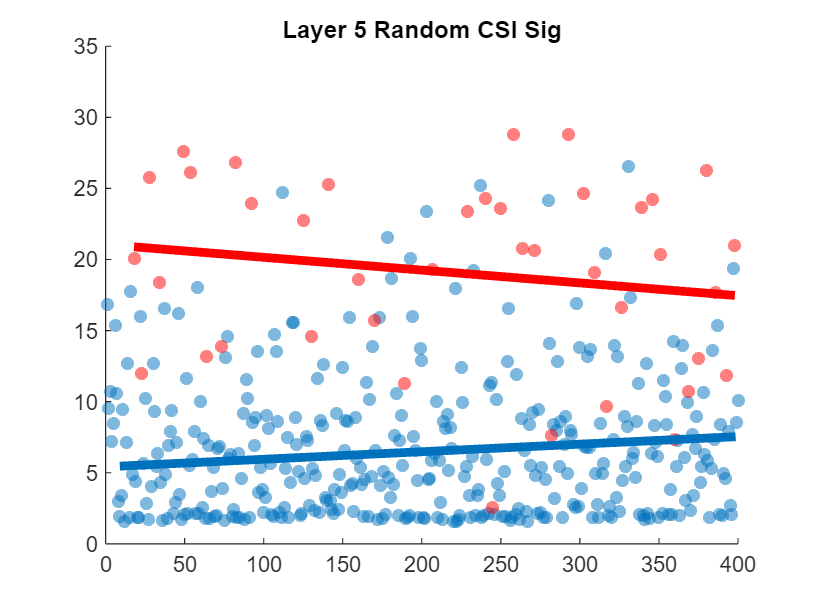

n = size(AllSpikeTable_Significance,1);
figure
title ('Layer 5 Random CSI Sig')
hold on
scatter(STDTrialsComplete(1).STDtrials(1:40), STDcount./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(AllSTDtrialsRest(1).STDtrials, STDcountRest./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./n,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
ylim([0,35])

% % scatter(STDTrialsComplete(1).STDtrials(1:40), STDcount./max(STDcount),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% % scatter(AllSTDtrialsRest(1).STDtrials, STDcountRest./max(STDcountRest),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% % s=findobj(gca,'Type','Scatter');
% % X = s.XData;
% % Y = s.YData;
% % f1 = polyfit(X,Y,3)
% % y1 = polyval(f1,X);
% % plot(X,y1)
% % scatter(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./max(DEVcount),'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
% % f2 = polyfit(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./max(DEVcount),3)
% % y2 = polyval(f2,ODDTrialsComplete(1).ODDtrials(1:40));
% % plot(ODDTrialsComplete(1).ODDtrials(1:40),y2)

        p = polyfit(STDTrialsComplete(1).STDtrials(1:40), STDcount./n, 1);
        px = [min(STDTrialsComplete(1).STDtrials(1:40)) max(STDTrialsComplete(1).STDtrials(1:40))];
        py = polyval(p, px);
        % plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);

        p_r = polyfit(AllSTDtrialsRest(1).STDtrials, STDcountRest./n, 1);
        px_r = [min(AllSTDtrialsRest(1).STDtrials) max(AllSTDtrialsRest(1).STDtrials)];
        py_r = polyval(p_r, px_r);
        % plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--');


        P= (p+p_r)./2;
        Px = (px+px_r)./2;
        Py = polyval(P, Px);
        plot(Px, Py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);


        p = polyfit(ODDTrialsComplete(1).ODDtrials(1:40),DEVcount./n, 1);
        px = [min(ODDTrialsComplete(1).ODDtrials(1:40)) max(ODDTrialsComplete(1).ODDtrials(1:40))];
        py = polyval(p, px);
        plot(px, py, 'LineWidth', 4,'Color',[1 0 0]);

% x = 0:400;
% y_dev = 5.3157 + (0.0033033) * x;
% plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])

% y_std = 2.7570 + (0.0021288) * x;
% plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])

cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer5_Sig_Random_SpkPerTrial_STD_DEV.tif');
saveas(gcf,['Layer5_Sig_Random_SpkPerTrial_STD_DEV.fig']);
saveas(gcf,['Layer5_Sig_Random_SpkPerTrial_STD_DEV.pdf']);

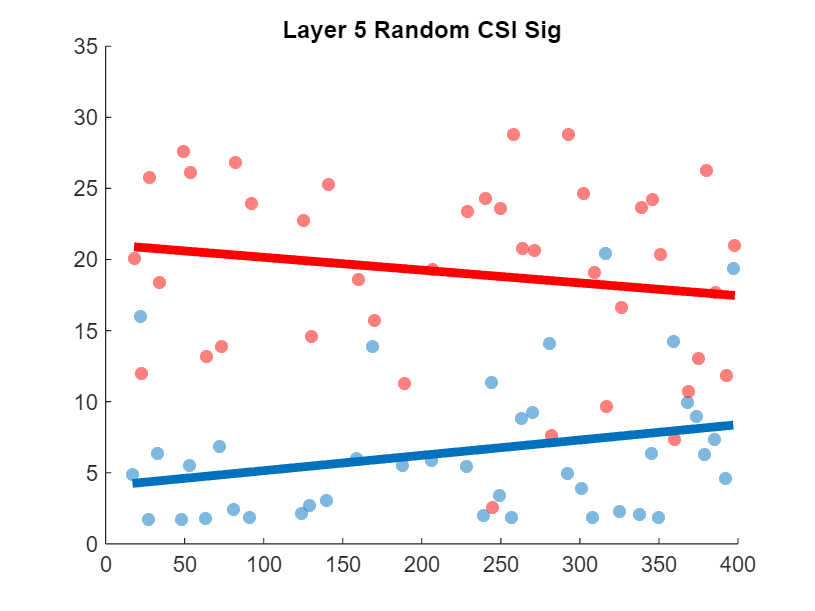

n = size(AllSpikeTable_Significance,1);
figure
title ('Layer 5 Random CSI Sig')
hold on
scatter(STDTrialsComplete(1).STDtrials(1:40), STDcount./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
%scatter(AllSTDtrialsRest(1).STDtrials, STDcountRest./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./n,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
ylim([0,35])

% % scatter(STDTrialsComplete(1).STDtrials(1:40), STDcount./max(STDcount),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% % scatter(AllSTDtrialsRest(1).STDtrials, STDcountRest./max(STDcountRest),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% % s=findobj(gca,'Type','Scatter');
% % X = s.XData;
% % Y = s.YData;
% % f1 = polyfit(X,Y,3)
% % y1 = polyval(f1,X);
% % plot(X,y1)
% % scatter(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./max(DEVcount),'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
% % f2 = polyfit(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./max(DEVcount),3)
% % y2 = polyval(f2,ODDTrialsComplete(1).ODDtrials(1:40));
% % plot(ODDTrialsComplete(1).ODDtrials(1:40),y2)

        p = polyfit(STDTrialsComplete(1).STDtrials(1:40), STDcount./n, 1);
        px = [min(STDTrialsComplete(1).STDtrials(1:40)) max(STDTrialsComplete(1).STDtrials(1:40))];
        py = polyval(p, px);
        plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);

        % p_r = polyfit(AllSTDtrialsRest(1).STDtrials, STDcountRest./n, 1);
        % px_r = [min(AllSTDtrialsRest(1).STDtrials) max(AllSTDtrialsRest(1).STDtrials)];
        % py_r = polyval(p_r, px_r);
        % % plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--');
        % 
        % 
        % P= (p+p_r)./2;
        % Px = (px+px_r)./2;
        % Py = polyval(P, Px);
        % plot(Px, Py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);


        p = polyfit(ODDTrialsComplete(1).ODDtrials(1:40),DEVcount./n, 1);
        px = [min(ODDTrialsComplete(1).ODDtrials(1:40)) max(ODDTrialsComplete(1).ODDtrials(1:40))];
        py = polyval(p, px);
        plot(px, py, 'LineWidth', 4,'Color',[1 0 0]);

% x = 0:400;
% y_dev = 5.3157 + (0.0033033) * x;
% plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])

% y_std = 2.7570 + (0.0021288) * x;
% plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])

cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer5_Sig_Random_SpkPerTrial_STD_B_DEV.tif');
saveas(gcf,['Layer5_Sig_Random_SpkPerTrial_STD_B_DEV.fig']);
saveas(gcf,['Layer5_Sig_Random_SpkPerTrial_STD_B_DEV.pdf']);

n = size(AllSpikeTable_Significance,1);
Nor=max(STDcountRest./n);
err=((STDcountRest./n)/Nor)./sqrt(size(STDcountRest,1))

err =     0.0353
    0.0200
    0.0225
    0.0151
    0.0179
    0.0323
    0.0222
    0.0063
    0.0041
    0.0072


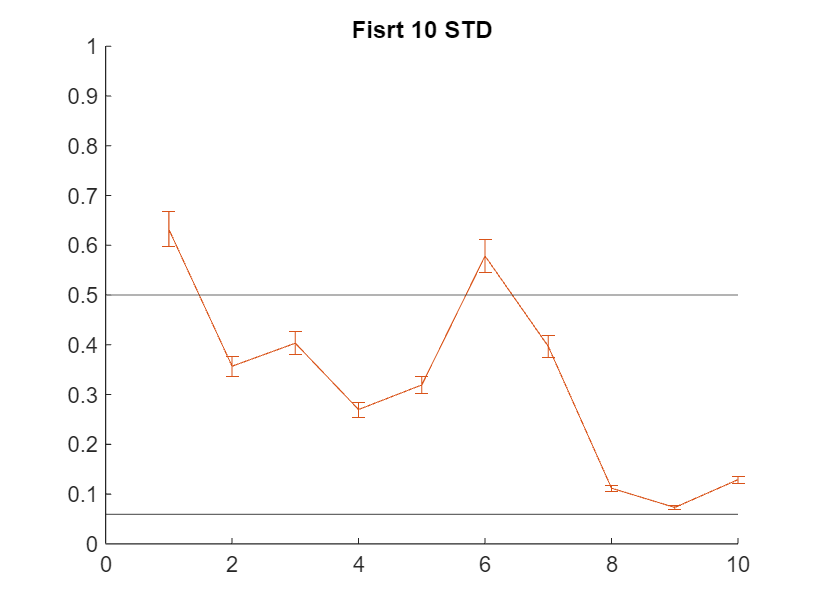

figure
% scatter(AllSTDtrialsRest(1).STDtrials(1:10), (STDcountRest(1:10)./n)/Nor,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
hold on
plot(AllSTDtrialsRest(1).STDtrials(1:10), (STDcountRest(1:10)./n)/Nor)
errorbar(AllSTDtrialsRest(1).STDtrials(1:10), (STDcountRest(1:10)./n)/Nor,err(1:10))
yline((min(STDcountRest./n))/Nor)
yline(0.5)
title ('Fisrt 10 STD')
ylim([0,1])
xlim([0,10])

% figure
% scatter(ODDTrialsCompleteP(1).ODDtrialsP(1:40), DEVcount_P./n,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
% title ('CA1 Periodic CSI Sig')
% hold on
% scatter(STDTrialsComplete_P(1).STDtrials(1:40), STDcount_P./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% scatter(AllSTDtrialsRest, STDcountRest,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% hold off
% cd ('C:\Jazmin\HIP\SpikePerCount')
% saveas(gcf,'HIP_Sig_Periodic_SpkPerTrial_STDbefore_DEV.tif');
% saveas(gcf,['HIP_Sig_Periodic_SpkPerTrial_STDbefore_DEV.fig']);
% saveas(gcf,['HIP_Sig_Periodic_SpkPerTrial_STDbefore_DEV.pdf']);

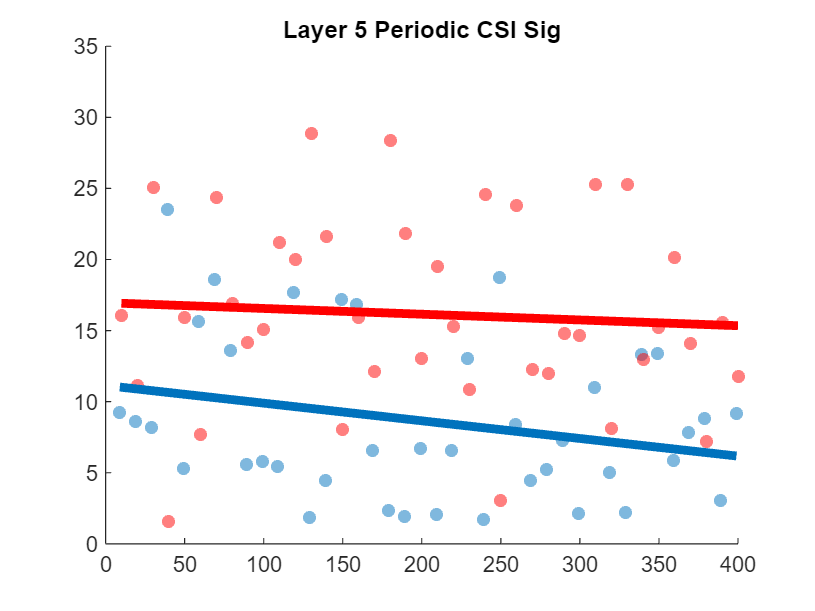

n = size(AllSpikeTable_Significance,1);
figure
title ('Layer 5 Periodic CSI Sig')
hold on
scatter(STDTrialsComplete_P(1).STDtrials(1:40), STDcount_P./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
%scatter(AllSTDtrialsRest_P(1).STDtrialsP, STDcountRest_P./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(ODDTrialsCompleteP(1).ODDtrialsP(1:40), DEVcount_P./n,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
ylim([0,35])
        p = polyfit(STDTrialsComplete_P(1).STDtrials(1:40), STDcount_P./n, 1);
        px = [min(STDTrialsComplete_P(1).STDtrials(1:40)) max(STDTrialsComplete_P(1).STDtrials(1:40))];
        py = polyval(p, px);
        plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);

        % p_r = polyfit(AllSTDtrialsRest_P(1).STDtrialsP, STDcountRest_P./n, 1);
        % px_r = [min(AllSTDtrialsRest_P(1).STDtrialsP) max(AllSTDtrialsRest_P(1).STDtrialsP)];
        % py_r = polyval(p_r, px_r);
        % % plot(px_r, py_r, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--');
        % 
        % P= (p+p_r)./2;
        % Px = (px+px_r)./2;
        % Py = polyval(P, Px);
        % plot(Px, Py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);


        p = polyfit(ODDTrialsCompleteP(1).ODDtrialsP(1:40),DEVcount_P./n, 1);
        px = [min(ODDTrialsCompleteP(1).ODDtrialsP(1:40)) max(ODDTrialsCompleteP(1).ODDtrialsP(1:40))];
        py = polyval(p, px);
        plot(px, py, 'LineWidth', 4,'Color',[1 0 0]);

% x = 0:400;
% y_dev = 5.9515 + (0.0018401) * x;
% plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])
% 
% y_std = 3.4611 + (0.00031385) * x;
% plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])
% 
% hold off
cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer5_Sig_Periodic_SpkPerTrial_STD_B_DEV.tif');
saveas(gcf,['Layer5_Sig_Periodic_SpkPerTrial_STD_B_DEV.fig']);
saveas(gcf,['Layer5_Sig_Periodic_SpkPerTrial_STD_B_DEV.pdf']);

n = size(AllSpikeTable_Significance,1);
%ODD R vs P
% ODD R referencia
Trials = [ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP];
Response = [DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n];
Group = [ones(40,1); ones(360,1)*2; ones(40,1)*3; ones(360,1)*4];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           21.053       1.7105     12.308    5.5637e-32
    Tiempo            -0.0089987    0.0067222    -1.3386       0.18107
    Grupo_2               -14.58       1.7962     -8.117    1.8223e-15
    Grupo_3              -4.0925       2.3958    -1.7082       0.08799
    Grupo_4              -13.421       1.7963    -7.4713    2.1016e-13
    Tiempo:Grupo_2       0.01017    0.0071373     1.4249       0.15459
    Tiempo:Grupo_3     0.0049553    0.0097996    0.50566       0.61324
    Tiempo:Gru

anova(modelo, 'summary') % Prueba de significancia de los efectos

ans = 5×5 table
                   SumSq     DF     MeanSq      F         pValue  
                   ______    ___    ______    ______    __________

    Total           29724    799    37.201                        
    Model          8260.3      7      1180    43.544    3.9626e-52
    . Linear       8197.1      4    2049.3    75.619     2.587e-54
    . Nonlinear    63.187      3    21.062    0.7772       0.50686
    Residual        21463    792      27.1                        


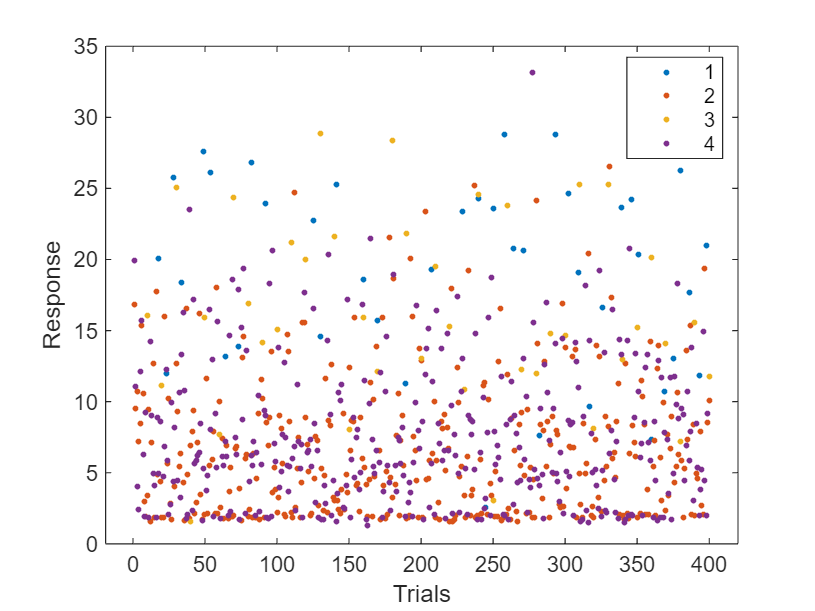


%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           21.053       1.7105     12.308    5.5637e-32
    Tiempo            -0.0089987    0.0067222    -1.3386       0.18107
    Grupo_2               -14.58       1.7962     -8.117    1.8223e-15
    Grupo_3              -4.0925       2.3958    -1.7082       0.08799
    Grupo_4              -13.421       1.7963    -7.4713    2.1016e-13
    Tiempo:Grupo_2       0.01017    0.0071373     1.4249       0.15459
    Tiempo:Grupo_3     0.0049553    0.0097996    0.50566       0.61324
    Tiemp

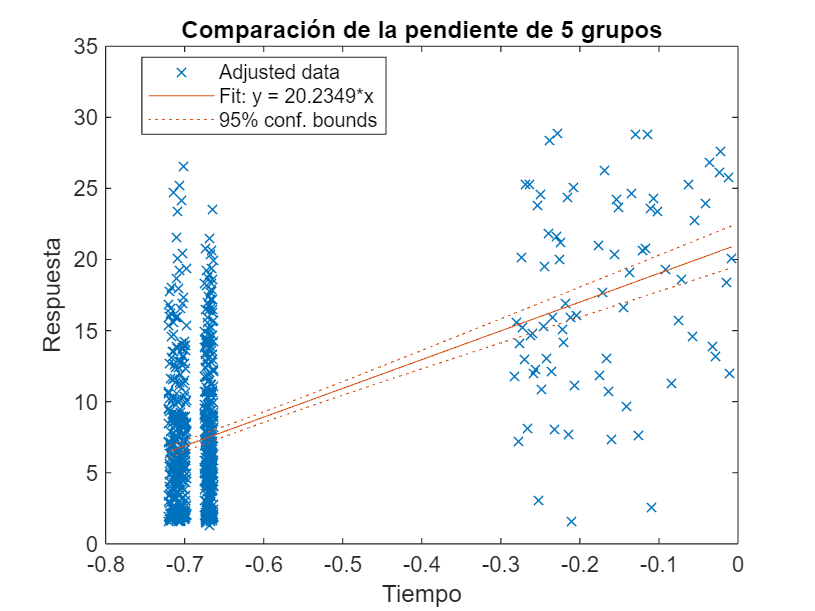

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD R vs P
% STD R referencia
Trials = [STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsComplete(1).ODDtrials(1:40);ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP];
Response = [STDcount./n;STDcountRest./n;DEVcount./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n];
Group = [ones(360,1)*2; ones(40,1); ones(40,1)*3; ones(360,1)*4];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           21.053       1.7105     12.308    5.5637e-32
    Tiempo            -0.0089987    0.0067222    -1.3386       0.18107
    Grupo_2               -14.58       1.7962     -8.117    1.8223e-15
    Grupo_3              -4.0925       2.3958    -1.7082       0.08799
    Grupo_4              -13.421       1.7963    -7.4713    2.1016e-13
    Tiempo:Grupo_2       0.01017    0.0071373     1.4249       0.15459
    Tiempo:Grupo_3     0.0049553    0.0097996    0.50566       0.61324
    Tiempo:Gru

anova(modelo, 'summary') % Prueba de significancia de los efectos

ans = 5×5 table
                   SumSq     DF     MeanSq      F         pValue  
                   ______    ___    ______    ______    __________

    Total           29724    799    37.201                        
    Model          8260.3      7      1180    43.544    3.9626e-52
    . Linear       8197.1      4    2049.3    75.619     2.587e-54
    . Nonlinear    63.187      3    21.062    0.7772       0.50686
    Residual        21463    792      27.1                        



%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           21.053       1.7105     12.308    5.5637e-32
    Tiempo            -0.0089987    0.0067222    -1.3386       0.18107
    Grupo_2               -14.58       1.7962     -8.117    1.8223e-15
    Grupo_3              -4.0925       2.3958    -1.7082       0.08799
    Grupo_4              -13.421       1.7963    -7.4713    2.1016e-13
    Tiempo:Grupo_2       0.01017    0.0071373     1.4249       0.15459
    Tiempo:Grupo_3     0.0049553    0.0097996    0.50566       0.61324
    Tiemp

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD R vs P
% ODD P referencia
Trials = [ODDTrialsCompleteP(1).ODDtrialsP(1:40);ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP];
Response = [DEVcount_P./n;DEVcount./n;STDcount./n;STDcountRest./n;STDcount_P./n;STDcountRest_P./n];
Group = [ ones(40,1)*1; ones(40,1)*2; ones(360,1)*3; ones(360,1)*4];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

%% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)            16.96       1.6776       10.11    1.1059e-22
    Tiempo            -0.0040434    0.0071305    -0.56706       0.57084
    Grupo_2               4.0925       2.3958      1.7082       0.08799
    Grupo_3              -10.487       1.7649     -5.9421    4.2133e-09
    Grupo_4              -9.3285        1.765     -5.2851    1.6255e-07
    Tiempo:Grupo_2    -0.0049553    0.0097996    -0.50566       0.61324
    Tiempo:Grupo_3     0.0052144    0.0075231     0.69312       0.48844
    T


clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(6,1);
m_pvalues(3,1) = p_values(7,1);
m_pvalues(4,1) = p_values(8,1);


y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq     DF     MeanSq      F         pValue  
                   ______    ___    ______    ______    __________

    Total           29724    799    37.201                        
    Model          8260.3      7      1180    43.544    3.9626e-52
    . Linear       8197.1      4    2049.3    75.619     2.587e-54
    . Nonlinear    63.187      3    21.062    0.7772       0.50686
    Residual        21463    792      27.1                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m

correctedPValues =        NaN
    0.0000
    0.0000
    2.5343
       NaN



% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 4×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        4.4237e-22              2.2833      
           0.35196              2.4529      
        1.6853e-08              1.9537      
        6.5019e-07              2.5857      


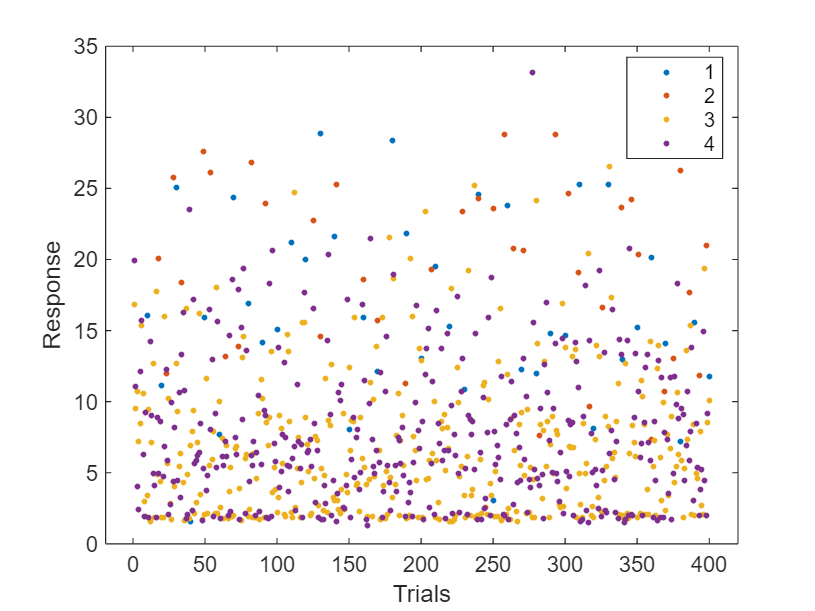

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)            16.96       1.6776       10.11    1.1059e-22
    Tiempo            -0.0040434    0.0071305    -0.56706       0.57084
    Grupo_2               4.0925       2.3958      1.7082       0.08799
    Grupo_3              -10.487       1.7649     -5.9421    4.2133e-09
    Grupo_4              -9.3285        1.765     -5.2851    1.6255e-07
    Tiempo:Grupo_2    -0.0049553    0.0097996    -0.50566       0.61324
    Tiempo:Grupo_3     0.0052144    0.0075231     0.69312       0.48844
    

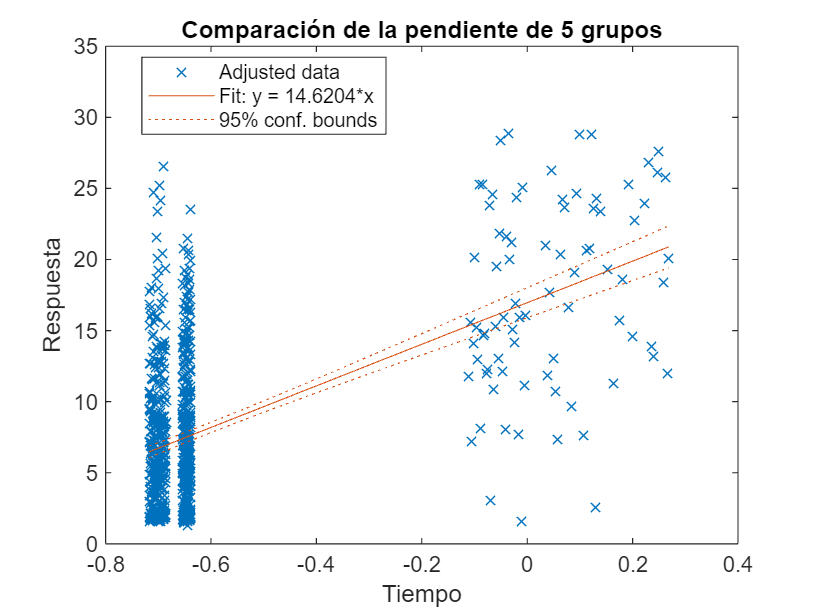

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD R vs P
% STD P referencia
Trials = [STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40)];
Response = [STDcount_P./n;STDcountRest_P./n;DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n];
Group = [ ones(360,1)*4;ones(40,1); ones(360,1)*2; ones(40,1)*3];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

%% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           21.053       1.7105     12.308    5.5637e-32
    Tiempo            -0.0089987    0.0067222    -1.3386       0.18107
    Grupo_2               -14.58       1.7962     -8.117    1.8223e-15
    Grupo_3              -4.0925       2.3958    -1.7082       0.08799
    Grupo_4              -13.421       1.7963    -7.4713    2.1016e-13
    Tiempo:Grupo_2       0.01017    0.0071373     1.4249       0.15459
    Tiempo:Grupo_3     0.0049553    0.0097996    0.50566       0.61324
    Tiempo:Gru


clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(6,1);
m_pvalues(3,1) = p_values(7,1);
m_pvalues(4,1) = p_values(8,1);


y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq     DF     MeanSq      F         pValue  
                   ______    ___    ______    ______    __________

    Total           29724    799    37.201                        
    Model          8260.3      7      1180    43.544    3.9626e-52
    . Linear       8197.1      4    2049.3    75.619     2.587e-54
    . Nonlinear    63.187      3    21.062    0.7772       0.50686
    Residual        21463    792      27.1                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 4×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        2.2255e-31             0.72428      
        7.2892e-15             0.61836      
           0.35196              2.4529      
        8.4066e-13             0.95537      


%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           21.053       1.7105     12.308    5.5637e-32
    Tiempo            -0.0089987    0.0067222    -1.3386       0.18107
    Grupo_2               -14.58       1.7962     -8.117    1.8223e-15
    Grupo_3              -4.0925       2.3958    -1.7082       0.08799
    Grupo_4              -13.421       1.7963    -7.4713    2.1016e-13
    Tiempo:Grupo_2       0.01017    0.0071373     1.4249       0.15459
    Tiempo:Grupo_3     0.0049553    0.0097996    0.50566       0.61324
    Tiemp

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

spike_counts_MSC = zeros(1,400);
for i = 1:40
spike_counts_MSC(1,CTRMSTrialsComplete_F1(1).CTRMStrials(i)) = MScount_F1(i,1)./n;
spike_counts_MSC(1,CTRMSTrialsComplete_F2(1).CTRMStrials(i)) = MScount_F2(i,1)./n;
end

for j = 1:320
spike_counts_MSC(1,MStrialsRest(1).MStrials(j)) = MScount_rest(j,1)./n;
end

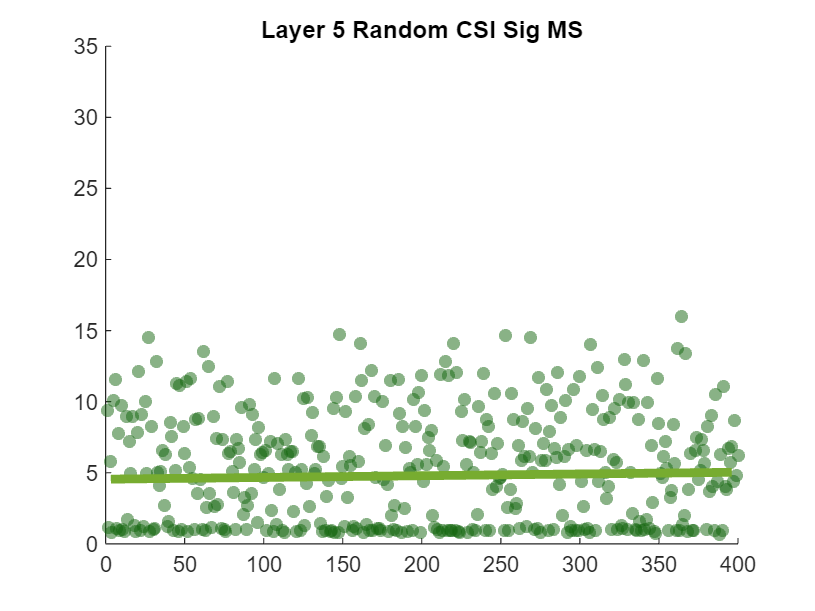

%MS
figure
scatter(CTRMSTrialsComplete_F1(1).CTRMStrials, MScount_F1./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
title ('Layer 5 Random CSI Sig MS')
hold on
scatter(CTRMSTrialsComplete_F2(1).CTRMStrials, MScount_F2./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
scatter(MStrialsRest(1).MStrials, MScount_rest./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
ylim([0,35])

        p1 = polyfit(CTRMSTrialsComplete_F1(1).CTRMStrials,MScount_F1./n, 1);
        px1 = [min(CTRMSTrialsComplete_F1(1).CTRMStrials) max(CTRMSTrialsComplete_F1(1).CTRMStrials)];
        py = polyval(p1, px1);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

         p2 = polyfit(CTRMSTrialsComplete_F2(1).CTRMStrials,MScount_F2./n, 1);
        px2 = [min(CTRMSTrialsComplete_F2(1).CTRMStrials) max(CTRMSTrialsComplete_F2(1).CTRMStrials)];
        py = polyval(p2, px2);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

         pT = polyfit(MStrialsRest(1).MStrials,MScount_rest./n, 1);
        pxT = [min(MStrialsRest(1).MStrials) max(MStrialsRest(1).MStrials)];
        py = polyval(pT, pxT);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

        P= (p1+p2+pT)./3;
        Px = (px1+px2+pxT)./3;
        py = polyval(P, Px);
        plot(Px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

% x = 0:400;
% y_msc = 2.2546 + (0.0019218) * x;
% plot(x,y_msc, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880])
% 
cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer5_Sig_SpkPerTrial_MS.tif');
saveas(gcf,['Layer5_Sig_SpkPerTrial_MS.fig']);
saveas(gcf,['Layer5_Sig_SpkPerTrial_MS.pdf']);

spike_counts_CASCASC = zeros(1,400);
for i = 1:40
spike_counts_CASCASC(1,CTR_ASC_F1TrialsComplete(1).CTRtrials(i)) = CASCasccount_F1(i,1)./n;
spike_counts_CASCASC(1,CTR_ASC_F2TrialsComplete(1).CTRtrials(i)) = CASCasccount_F2(i,1)./n;
end

for j = 1:320
spike_counts_CASCASC(1,CASCasctrialsRest(1).CASCasctrials(j)) = CASCasccount_rest(j,1)./n;
end

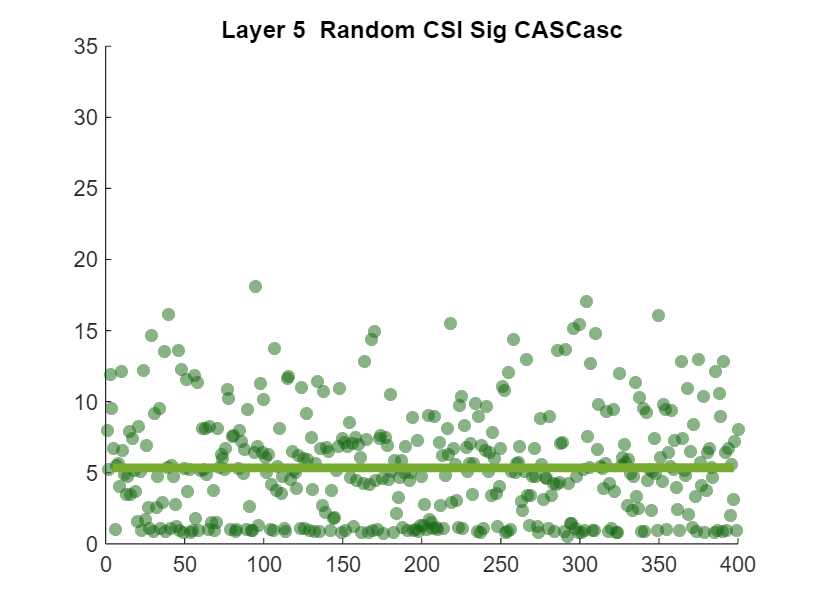

%CASCASC
figure
scatter(CTR_ASC_F1TrialsComplete(1).CTRtrials, CASCasccount_F1./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
title ('Layer 5  Random CSI Sig CASCasc')
hold on
scatter(CTR_ASC_F2TrialsComplete(1).CTRtrials, CASCasccount_F2./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
scatter(CASCasctrialsRest(1).CASCasctrials, CASCasccount_rest./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
% cd ('C:\Jazmin\HIP\SpikePerCount')
% saveas(gcf,'HIP_Sig_Random_SpkPerTrial_CASCASC.tif');
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.fig']);
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.pdf']);
ylim([0,35])

        p1 = polyfit(CTR_ASC_F1TrialsComplete(1).CTRtrials,CASCasccount_F1./n, 1);
        px1 = [min(CTR_ASC_F1TrialsComplete(1).CTRtrials) max(CTR_ASC_F1TrialsComplete(1).CTRtrials)];
        py = polyval(p1, px1);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

         p2 = polyfit(CTR_ASC_F2TrialsComplete(1).CTRtrials,CASCasccount_F2./n, 1);
        px2 = [min(CTR_ASC_F2TrialsComplete(1).CTRtrials) max(CTR_ASC_F2TrialsComplete(1).CTRtrials)];
        py = polyval(p2, px2);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

         pT = polyfit(CASCasctrialsRest(1).CASCasctrials,CASCasccount_rest./n, 1);
        pxT = [min(CASCasctrialsRest(1).CASCasctrials) max(CASCasctrialsRest(1).CASCasctrials)];
        py = polyval(pT, pxT);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

        P= (p1+p2+pT)./3;
        Px = (px1+px2+pxT)./3;
        py = polyval(P, Px);
        plot(Px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

% x = 0:400;
% y_cascasc = 2.5347 + (-0.00094849) * x;
% plot(x,y_cascasc, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880])
% 
cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer5_Sig_SpkPerTrial_CASCasc.tif');
saveas(gcf,['Layer5_Sig_SpkPerTrial_CASCasc.fig']);
saveas(gcf,['Layer5_Sig_SpkPerTrial_CASCasc.pdf']);

spike_counts_CASCDES = zeros(1,400);
for i = 1:40
spike_counts_CASCDES(1,CTR_DESC_F1TrialsComplete(1).CTRtrials(i)) = CASCdescount_F1(i,1)./n;
spike_counts_CASCDES(1,CTR_DESC_F2TrialsComplete(1).CTRtrials(i)) = CASCdescount_F2(i,1)./n;
end

for j = 1:320
spike_counts_CASCDES(1,CASCdestrialsRest(1).CASCdes(j)) = CASCdescount_rest(j,1)./n;
end

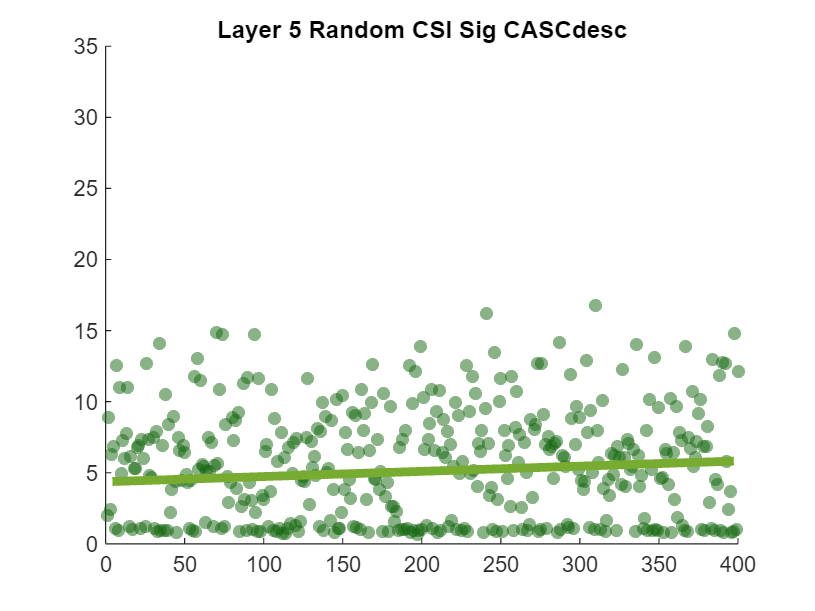

%CASCdesc
figure
scatter(CTR_DESC_F1TrialsComplete(1).CTRtrials, CASCdescount_F1./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
title ('Layer 5 Random CSI Sig CASCdesc')
hold on
scatter(CTR_DESC_F2TrialsComplete(1).CTRtrials, CASCdescount_F2./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
scatter(CASCdestrialsRest(1).CASCdes, CASCdescount_rest./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
% cd ('C:\Jazmin\HIP\SpikePerCount')
% saveas(gcf,'HIP_Sig_Random_SpkPerTrial_CASCASC.tif');
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.fig']);
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.pdf']);
ylim([0,35])
        p1 = polyfit(CTR_DESC_F1TrialsComplete(1).CTRtrials,CASCdescount_F1./n, 1);
        px1 = [min(CTR_DESC_F1TrialsComplete(1).CTRtrials) max(CTR_DESC_F1TrialsComplete(1).CTRtrials)];
        py = polyval(p1, px1);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

         p2 = polyfit(CTR_DESC_F2TrialsComplete(1).CTRtrials,CASCdescount_F2./n, 1);
        px2 = [min(CTR_DESC_F2TrialsComplete(1).CTRtrials) max(CTR_DESC_F2TrialsComplete(1).CTRtrials)];
        py = polyval(p2, px2);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

         pT = polyfit(CASCdestrialsRest(1).CASCdes,CASCdescount_rest./n, 1);
        pxT = [min(CASCdestrialsRest(1).CASCdes) max(CASCdestrialsRest(1).CASCdes)];
        py = polyval(pT, pxT);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

        P= (p1+p2+pT)./3;
        Px = (px1+px2+pxT)./3;
        py = polyval(P, Px);
        plot(Px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);
% 
% x = 0:400;
% y_cascdes = 2.6757 + (-0.0004692) * x;
% plot(x,y_cascdes, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880])
% 
cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer5_Sig_SpkPerTrial_CASCdes.tif');
saveas(gcf,['Layer5_Sig_SpkPerTrial_CASCdes.fig']);
saveas(gcf,['Layer5_Sig_SpkPerTrial_CASCdes.pdf']);

% figure
% x = 0:400;
% y_dev = 5.3157 + (0.0033033) * x;
% plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])
% ylim([0,16])
% hold on
% 
% y_std = 2.7570 + (0.0021288) * x;
% plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])
% 
% y_dev_p = 5.9515 + (0.0018401) * x;
% plot(x,y_dev_p, 'LineWidth', 4,'Color',[1 0 0],'linestyle','--')
% 
% y_std_p = 3.4611 + (0.00031385) * x;
% plot(x,y_std_p, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--')
% 
% y_msc = 2.2546 + (0.0019218) * x;
% plot(x,y_msc, 'LineWidth', 4,'Color','#14733C')
% 
% y_cascasc = 2.5347 + (-0.00094849) * x;
% plot(x,y_cascasc, 'LineWidth', 4,'Color','#5CBA47')
% 
% y_cascdes = 2.6757 + (-0.0004692) * x;
% plot(x,y_cascdes, 'LineWidth', 4,'Color','#5CBA47','linestyle','--')
% 
% cd ('D:\Jazmin\MultichannelDataTanks\HIP\SpikePerCount')
% saveas(gcf,'HIP_Fits.tif');
% saveas(gcf,['HIP_Fits.fig']);
% saveas(gcf,['HIP_Fits.pdf']);

%ODD vs the rest
% DEV R; STD R; DEV P; STD P; MS; CASC ASC; CASC DESC
Trials = [ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(40,1); ones(360,1)*2; ones(40,1)*3; ones(360,1)*4;ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           21.053       1.4599     14.421    6.5691e-45
    Tiempo            -0.0089987    0.0057376    -1.5684       0.11695
    Grupo_2               -14.58       1.5331    -9.5099    5.2985e-21
    Grupo_3              -4.0925       2.0449    -2.0014       0.04549
    Grupo_4              -13.421       1.5332    -8.7535    4.3333e-18
    Grupo_5               -15.74       1.5263    -10.312    2.5131e-24
    Grupo_6              -15.625       1.5263    -10.237    5.2691e-24
    Grupo_7   


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(9,1);
m_pvalues(3,1) = p_values(10,1);
m_pvalues(4,1) = p_values(11,1);
m_pvalues(5,1) = p_values(12,1);
m_pvalues(6,1) = p_values(13,1);
m_pvalues(7,1) = p_values(14,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);
y_pvalues(6,1) = p_values(7,1);
y_pvalues(7,1) = p_values(8,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue   
                   ______    ____    ______    ______    ___________

    Total           50945    1999    25.485                         
    Model           11736      13    902.76    45.727    4.1072e-103
    . Linear        11664       7    1666.2    84.399    1.1721e-107
    . Nonlinear    72.163       6    12.027    0.6092        0.72317
    Residual        39209    1986    19.743                         


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
    4.1072e-103       2.0536e-102    
    1.1721e-107       5.8603e-107    
        0.72317            3.6159    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        4.5984e-44             0.81868      
         3.709e-20             0.66639      
           0.31843              3.8754      
        3.0333e-17              1.1719      
        1.7592e-23             0.83581      
        3.6884e-23             0.95285      
        2.5028e-23              0.6734      


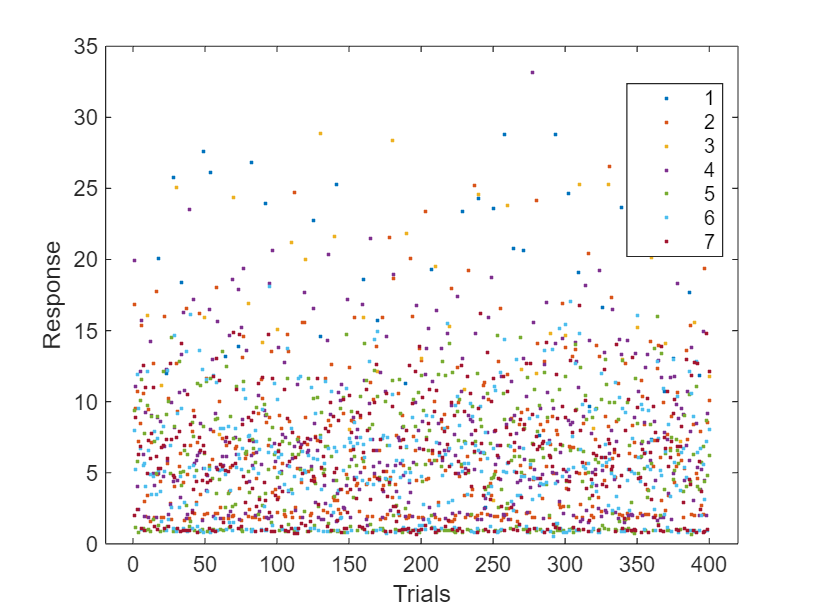

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           21.053       1.4599     14.421    6.5691e-45
    Tiempo            -0.0089987    0.0057376    -1.5684       0.11695
    Grupo_2               -14.58       1.5331    -9.5099    5.2985e-21
    Grupo_3              -4.0925       2.0449    -2.0014       0.04549
    Grupo_4              -13.421       1.5332    -8.7535    4.3333e-18
    Grupo_5               -15.74       1.5263    -10.312    2.5131e-24
    Grupo_6              -15.625       1.5263    -10.237    5.2691e-24
    Grupo

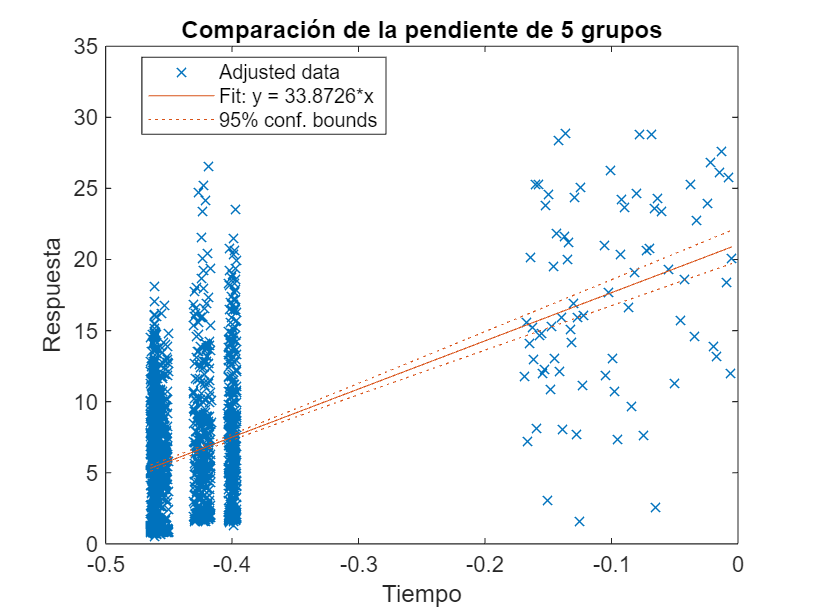

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%STD R vs the rest
% STD R; DEV R; DEV P; STD P; MS; CASC ASC; CASC DESC
Trials = [STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsComplete(1).ODDtrials(1:40);ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [STDcount./n;STDcountRest./n;DEVcount./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ ones(360,1)*1; ones(40,1)*2; ones(40,1)*3; ones(360,1)*4;ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            6.4728      0.46811       13.828    1.3753e-41
    Tiempo               0.001171    0.0020471      0.57202       0.56738
    Grupo_2                 14.58       1.5331       9.5099    5.2985e-21
    Grupo_3                10.487       1.5064       6.9619    4.5465e-12
    Grupo_4                 1.159       0.6622       1.7503      0.080227
    Grupo_5               -1.1597      0.64598      -1.7952      0.072776
    Grupo_6               -1.0449      0.64598      -1.6175       0.1


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue   
                   ______    ____    ______    ______    ___________

    Total           50945    1999    25.485                         
    Model           11736      13    902.76    45.727    4.1072e-103
    . Linear        11664       7    1666.2    84.399    1.1721e-107
    . Nonlinear    72.163       6    12.027    0.6092        0.72317
    Residual        39209    1986    19.743                         


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
    4.1072e-103       2.0536e-102    
    1.1721e-107       5.8603e-107    
        0.72317            3.6159    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        9.6274e-41              3.9716      
         3.709e-20             0.74144      
        3.1825e-11             0.61101      
           0.56159             0.66639      
           0.50943              2.9179      
        3.6884e-23             0.95285      
        2.5028e-23              0.6734      


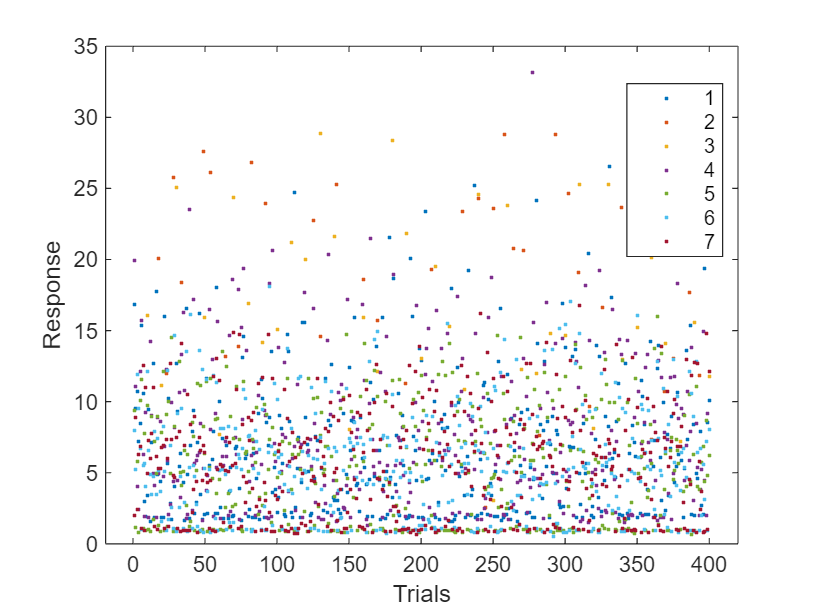

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            6.4728      0.46811       13.828    1.3753e-41
    Tiempo               0.001171    0.0020471      0.57202       0.56738
    Grupo_2                 14.58       1.5331       9.5099    5.2985e-21
    Grupo_3                10.487       1.5064       6.9619    4.5465e-12
    Grupo_4                 1.159       0.6622       1.7503      0.080227
    Grupo_5               -1.1597      0.64598      -1.7952      0.072776
    Grupo_6               -1.0449      0.64598      -1.6175     

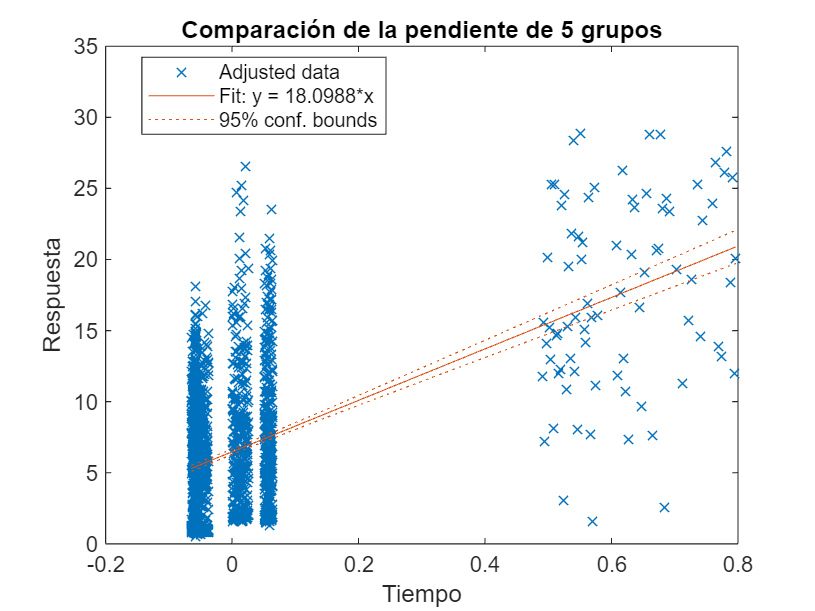

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD P vs the rest
% DEV P; DEV R; STD R; STD P; MS; CASC ASC; CASC DESC
Trials = [ODDTrialsCompleteP(1).ODDtrialsP(1:40);ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [DEVcount_P./n;DEVcount./n;STDcount./n;STDcountRest./n;STDcount_P./n;STDcountRest_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(40,1)*1; ones(40,1)*2; ones(360,1)*3; ones(360,1)*4;ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)            16.96       1.4318      11.845    2.5188e-31
    Tiempo            -0.0040434    0.0060861    -0.66437       0.50653
    Grupo_2               4.0925       2.0449      2.0014       0.04549
    Grupo_3              -10.487       1.5064     -6.9619    4.5465e-12
    Grupo_4              -9.3285       1.5065     -6.1921     7.194e-10
    Grupo_5              -11.647       1.4995     -7.7676    1.2721e-14
    Grupo_6              -11.532       1.4995     -7.6911    2.2801e-14
    G


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue   
                   ______    ____    ______    ______    ___________

    Total           50945    1999    25.485                         
    Model           11736      13    902.76    45.727    4.1072e-103
    . Linear        11664       7    1666.2    84.399    1.1721e-107
    . Nonlinear    72.163       6    12.027    0.6092        0.72317
    Residual        39209    1986    19.743                         


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
    4.1072e-103       2.0536e-102    
    1.1721e-107       5.8603e-107    
        0.72317            3.6159    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        1.7632e-30                3.5457    
           0.31843             1.596e-13    
        3.1825e-11            1.1759e-13    
        5.0358e-09                3.8754    
        8.9045e-14                2.9179    
        3.6884e-23               0.95285    
        2.5028e-23                0.6734    


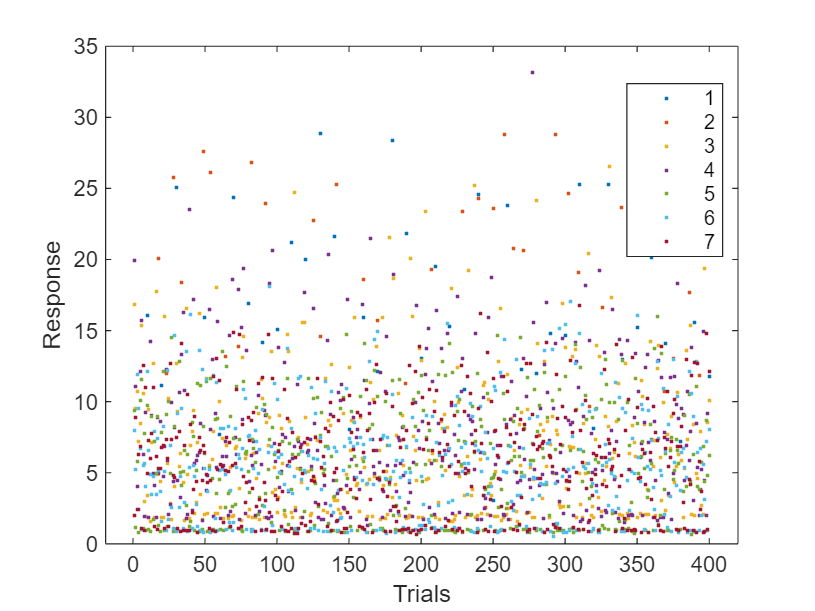

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)            16.96       1.4318      11.845    2.5188e-31
    Tiempo            -0.0040434    0.0060861    -0.66437       0.50653
    Grupo_2               4.0925       2.0449      2.0014       0.04549
    Grupo_3              -10.487       1.5064     -6.9619    4.5465e-12
    Grupo_4              -9.3285       1.5065     -6.1921     7.194e-10
    Grupo_5              -11.647       1.4995     -7.7676    1.2721e-14
    Grupo_6              -11.532       1.4995     -7.6911    2.2801e-14
    

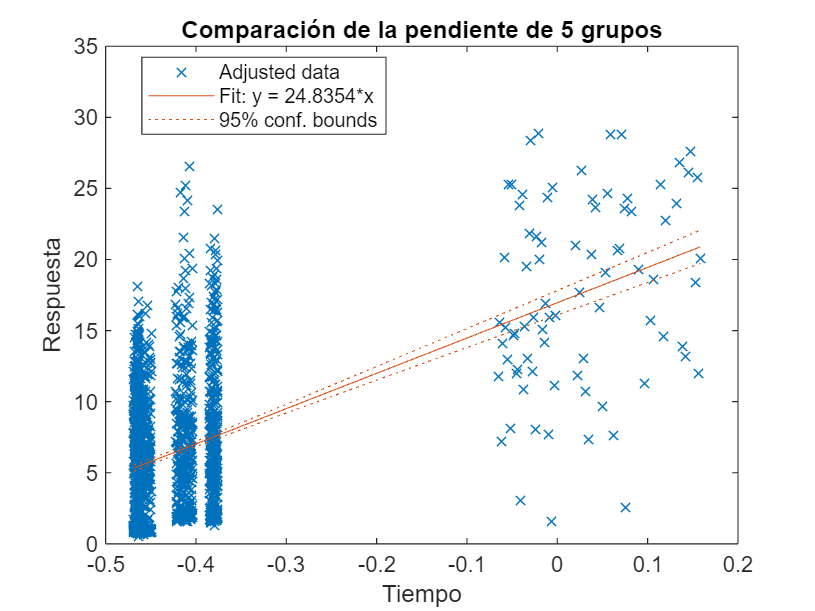

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%STD P vs the rest
% STD P; DEV R; STD R; DEV P; MS; CASC ASC; CASC DESC
Trials = [STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [STDcount_P./n;STDcountRest_P./n;DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(360,1)*1; ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           7.6319      0.46838      16.294    4.0258e-56
    Tiempo            -0.0005942    0.0020282    -0.29297       0.76958
    Grupo_2               13.421       1.5332      8.7535    4.3333e-18
    Grupo_3               -1.159       0.6622     -1.7503      0.080227
    Grupo_4               9.3285       1.5065      6.1921     7.194e-10
    Grupo_5              -2.3187      0.64618     -3.5883    0.00034093
    Grupo_6              -2.2039      0.64618     -3.4107    0.00066094
    G


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue   
                   ______    ____    ______    ______    ___________

    Total           50945    1999    25.485                         
    Model           11736      13    902.76    45.727    4.1072e-103
    . Linear        11664       7    1666.2    84.399    1.1721e-107
    . Nonlinear    72.163       6    12.027    0.6092        0.72317
    Residual        39209    1986    19.743                         


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
    4.1072e-103       2.0536e-102    
    1.1721e-107       5.8603e-107    
        0.72317            3.6159    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

         2.818e-55                5.387     
        3.0333e-17            0.0046266     
           0.56159            0.0032811     
        5.0358e-09               1.1719     
         0.0023865               3.7817     
        3.6884e-23              0.95285     
        2.5028e-23               0.6734     


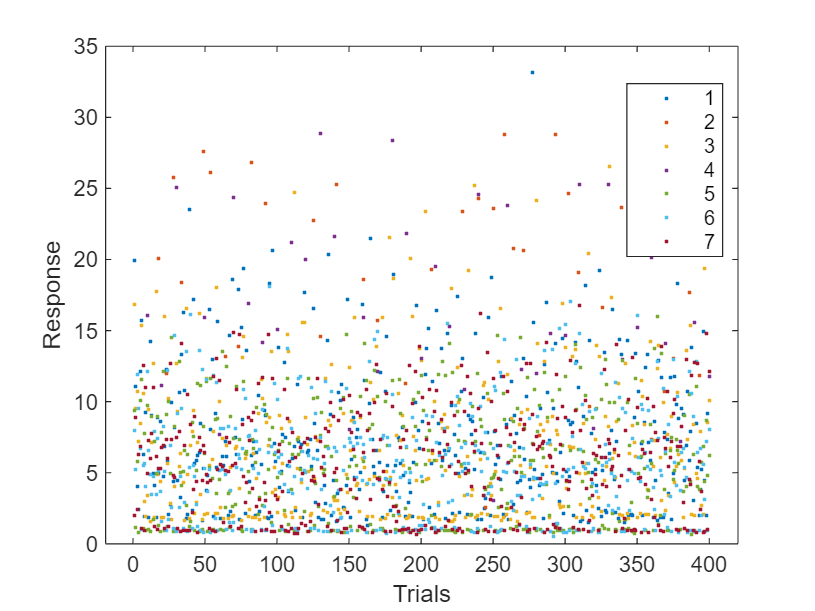

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           7.6319      0.46838      16.294    4.0258e-56
    Tiempo            -0.0005942    0.0020282    -0.29297       0.76958
    Grupo_2               13.421       1.5332      8.7535    4.3333e-18
    Grupo_3               -1.159       0.6622     -1.7503      0.080227
    Grupo_4               9.3285       1.5065      6.1921     7.194e-10
    Grupo_5              -2.3187      0.64618     -3.5883    0.00034093
    Grupo_6              -2.2039      0.64618     -3.4107    0.00066094
    

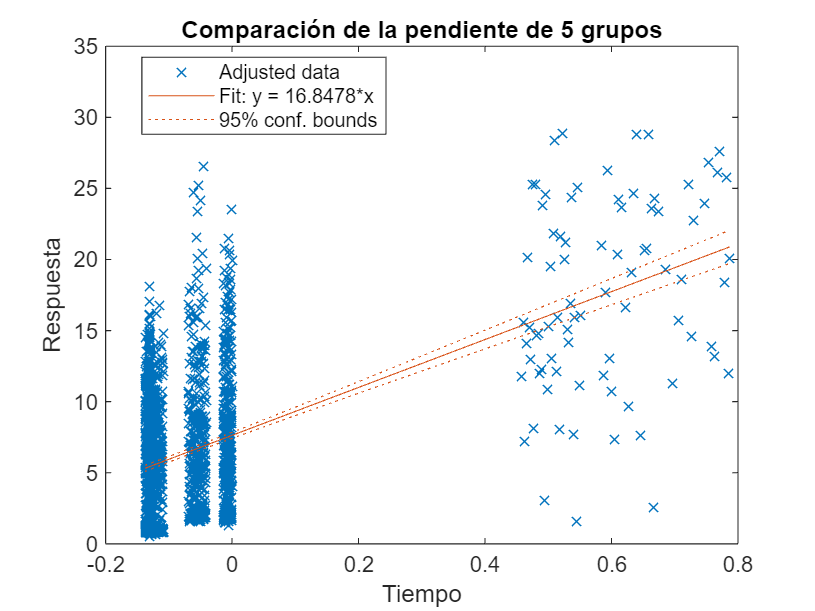

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%MS vs the rest
% MS; DEV R; STD R; DEV P; STD P; CASC ASC; CASC DESC
Trials = [CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [MScount_F1./n;MScount_F2./n; MScount_rest./n;DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(400,1)*1; ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(360,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE         tStat        pValue  
                      ___________    _________    ________    __________

    (Intercept)            5.3132      0.44516      11.935    9.1745e-32
    Tiempo             0.00042947     0.001924     0.22322       0.82339
    Grupo_2                 15.74       1.5263      10.312    2.5131e-24
    Grupo_3                1.1597      0.64598      1.7952      0.072776
    Grupo_4                11.647       1.4995      7.7676    1.2721e-14
    Grupo_5                2.3187      0.64618      3.5883    0.00034093
    Grupo_6               0.11475      0.62955     0.18228       0.85538
    


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue   
                   ______    ____    ______    ______    ___________

    Total           50945    1999    25.485                         
    Model           11736      13    902.76    45.727    4.1072e-103
    . Linear        11664       7    1666.2    84.399    1.1721e-107
    . Nonlinear    72.163       6    12.027    0.6092        0.72317
    Residual        39209    1986    19.743                         


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
    4.1072e-103       2.0536e-102    
    1.1721e-107       5.8603e-107    
        0.72317            3.6159    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        6.4222e-31              5.7637      
        1.7592e-23              5.9877      
           0.50943              6.5167      
        8.9045e-14             0.83581      
         0.0023865              5.5429      
        3.6884e-23             0.95285      
        2.5028e-23              0.6734      


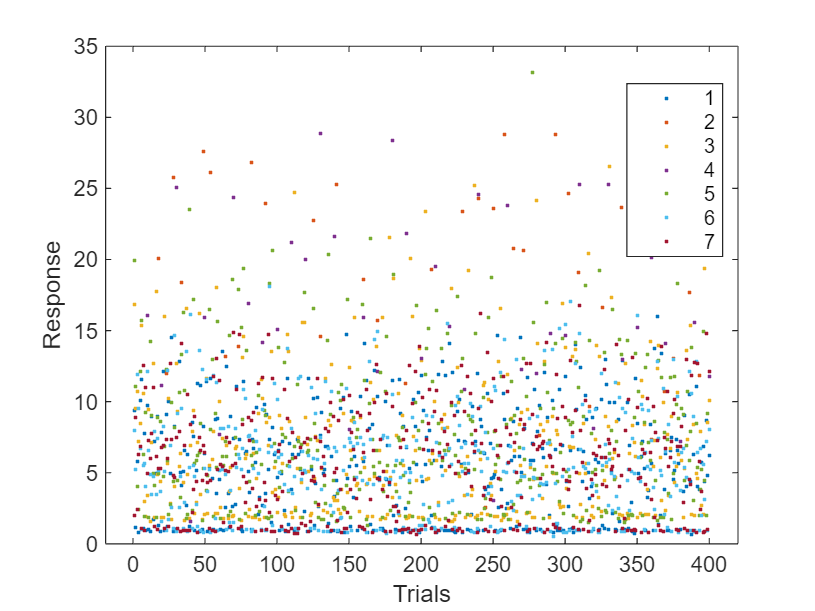

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE         tStat        pValue  
                      ___________    _________    ________    __________

    (Intercept)            5.3132      0.44516      11.935    9.1745e-32
    Tiempo             0.00042947     0.001924     0.22322       0.82339
    Grupo_2                 15.74       1.5263      10.312    2.5131e-24
    Grupo_3                1.1597      0.64598      1.7952      0.072776
    Grupo_4                11.647       1.4995      7.7676    1.2721e-14
    Grupo_5                2.3187      0.64618      3.5883    0.00034093
    Grupo_6               0.11475      0.62955     0.18228       0.85538

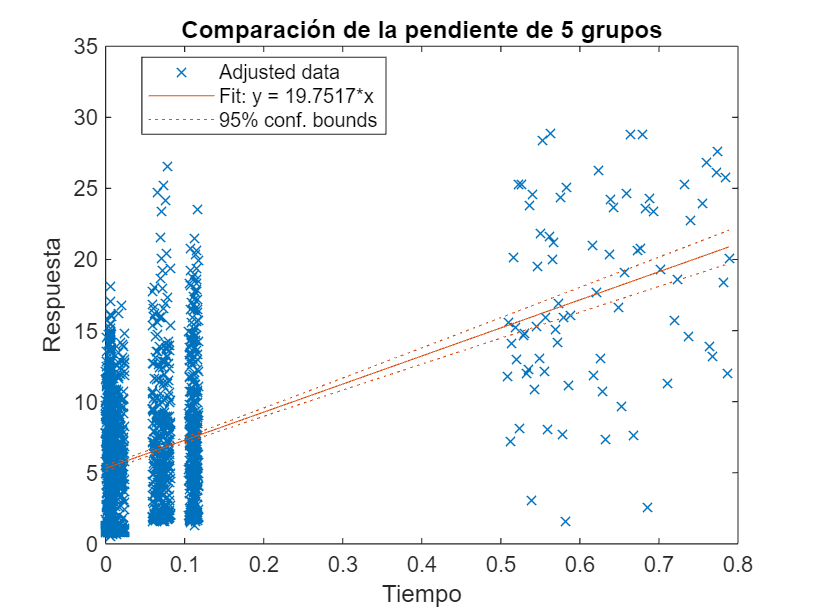

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%CASC ASC vs the rest
% CASC ASC; DEV R; STD R; DEV P; STD P; MS; CASC DESC
Trials = [CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(400,1)*1;ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(360,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            5.4279      0.44516       12.193    4.9621e-33
    Tiempo             2.4222e-05     0.001924      0.01259       0.98996
    Grupo_2                15.625       1.5263       10.237    5.2691e-24
    Grupo_3                1.0449      0.64598       1.6175       0.10592
    Grupo_4                11.532       1.4995       7.6911    2.2801e-14
    Grupo_5                2.2039      0.64618       3.4107    0.00066094
    Grupo_6              -0.11475      0.62955     -0.18228       0.8


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue   
                   ______    ____    ______    ______    ___________

    Total           50945    1999    25.485                         
    Model           11736      13    902.76    45.727    4.1072e-103
    . Linear        11664       7    1666.2    84.399    1.1721e-107
    . Nonlinear    72.163       6    12.027    0.6092        0.72317
    Residual        39209    1986    19.743                         


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
    4.1072e-103       2.0536e-102    
    1.1721e-107       5.8603e-107    
        0.72317            3.6159    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        3.4735e-32              6.9297      
        3.6884e-23              5.9877      
           0.74144              6.4668      
         1.596e-13             0.95285      
         0.0046266              4.7822      
        3.6884e-23             0.95285      
        2.5028e-23              0.6734      


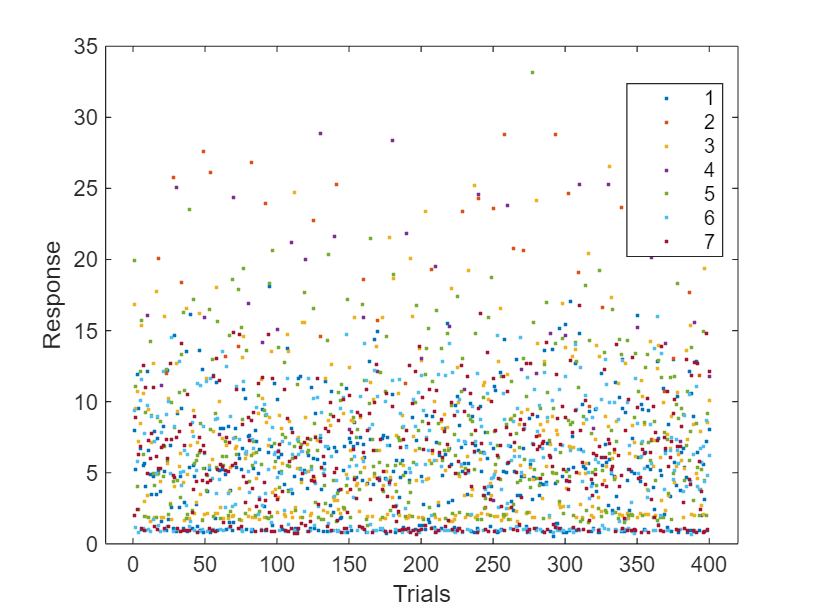

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            5.4279      0.44516       12.193    4.9621e-33
    Tiempo             2.4222e-05     0.001924      0.01259       0.98996
    Grupo_2                15.625       1.5263       10.237    5.2691e-24
    Grupo_3                1.0449      0.64598       1.6175       0.10592
    Grupo_4                11.532       1.4995       7.6911    2.2801e-14
    Grupo_5                2.2039      0.64618       3.4107    0.00066094
    Grupo_6              -0.11475      0.62955     -0.18228     

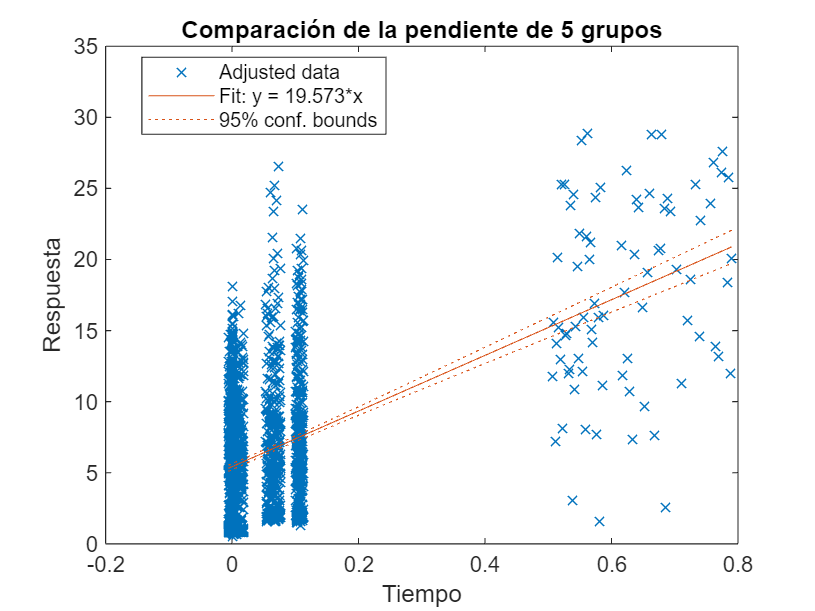

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%CASC DESC vs the rest
% CASC DESC; DEV R; STD R; DEV P; STD P; MS; CASC ASC
Trials = [CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials];
    Response = [CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n;DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n];
Group = [ones(400,1)*1; ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(360,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            5.3677      0.44516       12.058    2.3074e-32
    Tiempo              0.0010733     0.001924      0.55785       0.57701
    Grupo_2                15.685       1.5263       10.277    3.5755e-24
    Grupo_3                1.1051      0.64598       1.7107      0.087287
    Grupo_4                11.593       1.4995       7.7312    1.6799e-14
    Grupo_5                2.2641      0.64618       3.5039    0.00046873
    Grupo_6             -0.054556      0.62955    -0.086659       0.9


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq      F         pValue   
                   ______    ____    ______    ______    ___________

    Total           50945    1999    25.485                         
    Model           11736      13    902.76    45.727    4.1072e-103
    . Linear        11664       7    1666.2    84.399    1.1721e-107
    . Nonlinear    72.163       6    12.027    0.6092        0.72317
    Residual        39209    1986    19.743                         


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
    4.1072e-103       2.0536e-102    
    1.1721e-107       5.8603e-107    
        0.72317            3.6159    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        1.6152e-31              4.0391      
        2.5028e-23              6.5167      
           0.61101              6.4668      
        1.1759e-13              0.6734      
         0.0032811              6.8058      
        3.6884e-23             0.95285      
        2.5028e-23              0.6734      


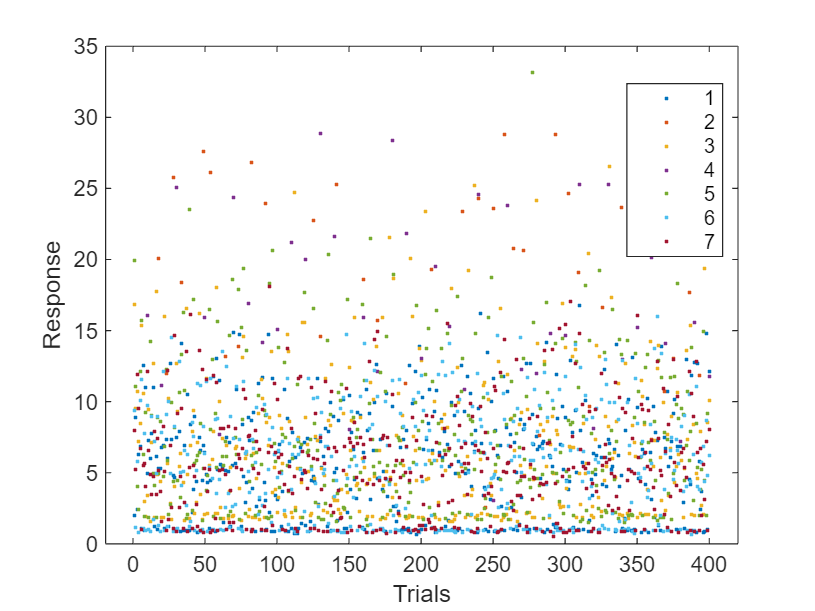

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            5.3677      0.44516       12.058    2.3074e-32
    Tiempo              0.0010733     0.001924      0.55785       0.57701
    Grupo_2                15.685       1.5263       10.277    3.5755e-24
    Grupo_3                1.1051      0.64598       1.7107      0.087287
    Grupo_4                11.593       1.4995       7.7312    1.6799e-14
    Grupo_5                2.2641      0.64618       3.5039    0.00046873
    Grupo_6             -0.054556      0.62955    -0.086659     

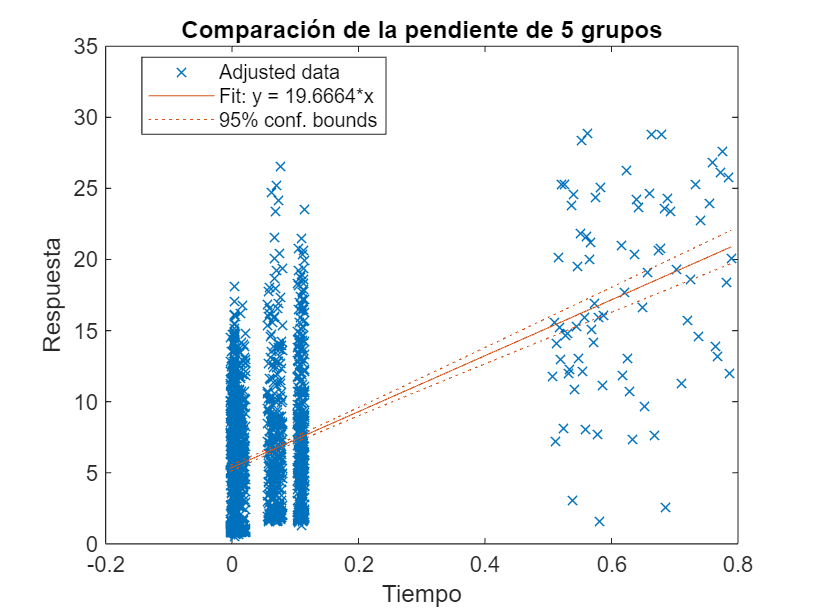

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%STD vs CTR
Trials = [STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [STDcount./n;STDcountRest./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(360,1)*2; ones(400,1)*3; ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            6.4728      0.43648        14.83    1.2486e-46
    Tiempo               0.001171    0.0019088      0.61347       0.53965
    Grupo_3               -1.1597      0.60233      -1.9253      0.054376
    Grupo_4               -1.0449      0.60233      -1.7348       0.08298
    Grupo_5               -1.1051      0.60233      -1.8347       0.06674
    Tiempo:Grupo_3    -0.00074152    0.0026195     -0.28307       0.77716
    Tiempo:Grupo_4     -0.0011468    0.0026195     -0.43778       0.6


clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(6,1);
m_pvalues(3,1) = p_values(7,1);
m_pvalues(4,1) = p_values(8,1);


y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq       F          pValue  
                   ______    ____    ______    ________    __________

    Total           27082    1559    17.371                          
    Model          442.26       7    63.179      3.6808    0.00059475
    . Linear       437.68       4    109.42      6.3747    4.3621e-05
    . Nonlinear    4.5803       3    1.5268    0.088949       0.96613
    Residual        26639    1552    17.164                          


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 4×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        4.9945e-46              2.1586      
            0.2175              3.1086      
           0.33192              2.6464      
           0.26696               3.881      


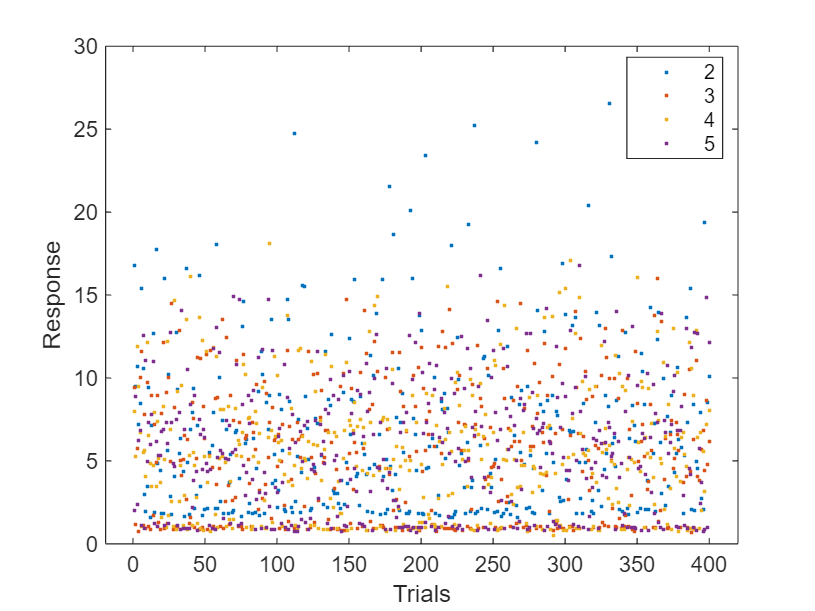

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

%CTR MS vs CASC
Trials = [CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(400,1)*3; ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE         tStat        pValue  
                      ___________    _________    ________    __________

    (Intercept)            5.3132      0.38624      13.756    4.4681e-40
    Tiempo             0.00042947    0.0016693     0.25727       0.79701
    Grupo_4               0.11475      0.54622     0.21008       0.83364
    Grupo_5              0.054556      0.54622    0.099879       0.92046
    Tiempo:Grupo_4    -0.00040525    0.0023608    -0.17166       0.86373
    Tiempo:Grupo_5     0.00064382    0.0023608     0.27271       0.78512


Number of observations: 1200, Error degrees of freedom: 1194
Root Mean Squared Error: 3.86
R



clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(5,1);
m_pvalues(3,1) = p_values(6,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq       F       pValue 
                   ______    ____    ______    _______    _______

    Total           17760    1199    14.813                      
    Model          14.783       5    2.9565    0.19893    0.96293
    . Linear       11.797       3    3.9324    0.26459    0.85094
    . Nonlinear    2.9854       2    1.4927    0.10044    0.90445
    Residual        17745    1194    14.862                      


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 3×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        1.3404e-39               2.391      
            2.5009              2.5912      
            2.7614              2.3554      


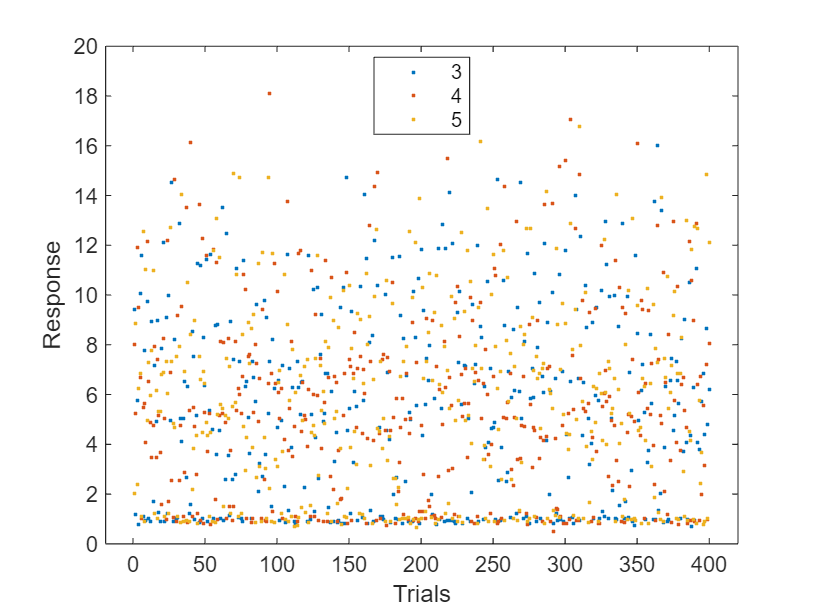

%%%%%%%%%%%%%%%%%%%%%%%
figure;
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

% ASC vs DESC
Trials = [CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.4279      0.38466      14.111    1.6162e-40
    Tiempo            2.4222e-05    0.0016625     0.01457       0.98838
    Grupo_5            -0.060197        0.544    -0.11066       0.91192
    Tiempo:Grupo_5     0.0010491    0.0023512     0.44619       0.65558


Number of observations: 800, Error degrees of freedom: 796
Root Mean Squared Error: 3.84
R-squared: 0.000907,  Adjusted R-Squared: -0.00286
F-statistic vs. constant model: 0.241, p-value = 0.868



% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m = length(p_values); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = p_values * m; 
% Display results
clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(4,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq     DF     MeanSq       F       pValue 
                   ______    ___    ______    _______    _______

    Total           11745    799    14.699                      
    Model          10.655      3    3.5518    0.24094    0.86779
    . Linear       7.7207      2    3.8603    0.26187    0.76968
    . Nonlinear    2.9348      1    2.9348    0.19909    0.65558
    Residual        11734    796    14.741                      


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 2×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        3.2324e-40              1.9768      
            1.8238              1.3112      


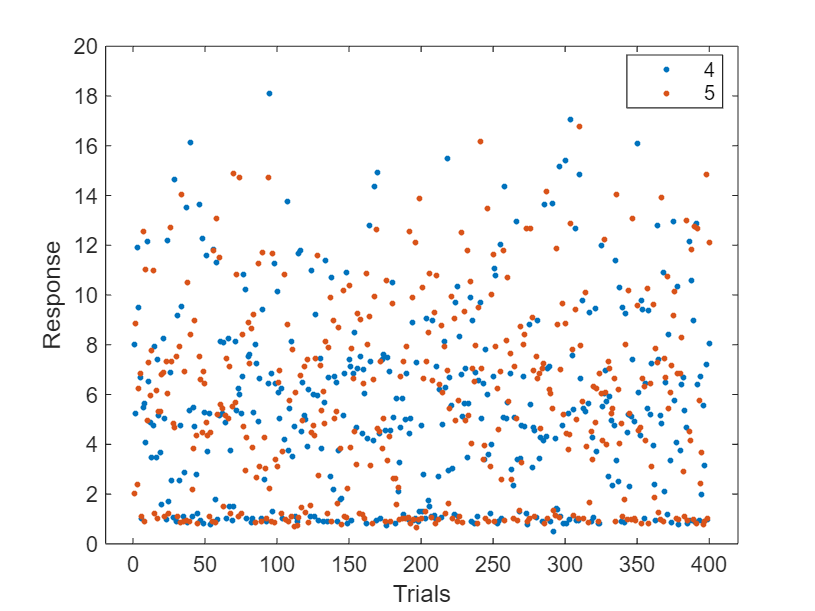

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

% DESC vs ASC 
Trials = [CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials];
Response = [CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n];
Group = [ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           5.4279      0.38466      14.111    1.6162e-40
    Tiempo            2.4222e-05    0.0016625     0.01457       0.98838
    Grupo_5            -0.060197        0.544    -0.11066       0.91192
    Tiempo:Grupo_5     0.0010491    0.0023512     0.44619       0.65558


Number of observations: 800, Error degrees of freedom: 796
Root Mean Squared Error: 3.84
R-squared: 0.000907,  Adjusted R-Squared: -0.00286
F-statistic vs. constant model: 0.241, p-value = 0.868



% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m = length(p_values); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = p_values * m; 
% Display results
clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);

m_pvalues = 0.9884

m_pvalues(2,1) = p_values(4,1);

m_pvalues =     0.9884
    0.6556



y_pvalues(1,1) = p_values(1,1);

y_pvalues = 1.6162e-40

y_pvalues(2,1) = p_values(3,1);

y_pvalues =     0.0000
    0.9119




m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq     DF     MeanSq       F       pValue 
                   ______    ___    ______    _______    _______

    Total           11745    799    14.699                      
    Model          10.655      3    3.5518    0.24094    0.86779
    . Linear       7.7207      2    3.8603    0.26187    0.76968
    . Nonlinear    2.9348      1    2.9348    0.19909    0.65558
    Residual        11734    796    14.741                      


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 2×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        3.2324e-40              1.9768      
            1.8238              1.3112      


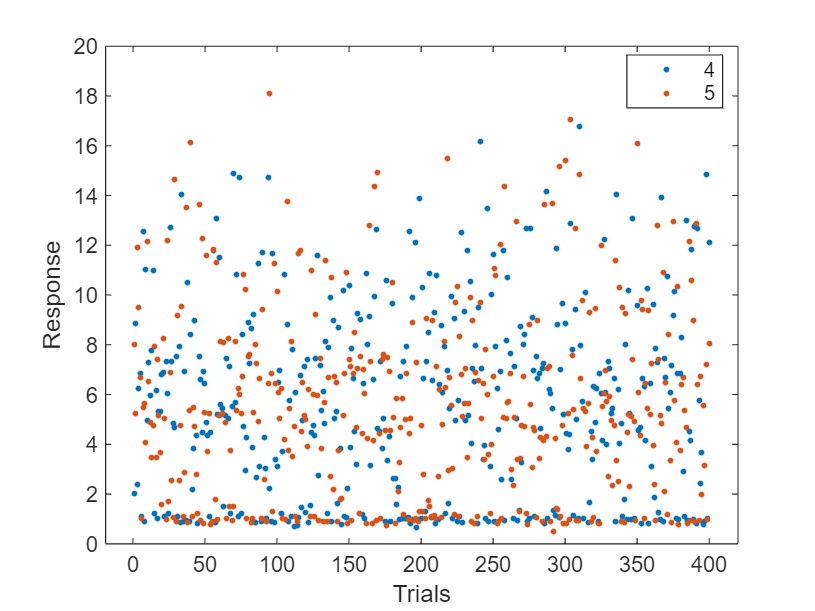

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

MScount_F1V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,13));
        for i = 1:size(MStimes_F1{1,1},1)
            if MStimes_F1{1,1}(i) >= 200 && MStimes_F1{1,1}(i) <= 800
                MScount_F1V(k,j) = MScount_F1V(k,j) + 1;
            end
        end
    end
end

MScount_F2V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,12));
        for i = 1:size(MStimes_F2{1,1},1)
            if MStimes_F2{1,1}(i) >= 200 && MStimes_F2{1,1}(i) <= 800
                MScount_F2V(k,j) = MScount_F2V(k,j) + 1;
            end
        end
    end
end

MScount_restV = zeros(320,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        MStimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,11));
        for i = 1:size(MStimesRest{1,1},1)
            if MStimesRest{1,1}(i) >= 200 && MStimesRest{1,1}(i) <= 800
                MScount_restV(k,j) = MScount_restV(k,j) + 1;
            end
        end
    end
end

CASCasccount_F1V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,15));
        for i = 1:size(CASCasctimes_F1{1,1},1)
            if CASCasctimes_F1{1,1}(i) >= 200 && CASCasctimes_F1{1,1}(i) <= 800
                CASCasccount_F1V(k,j) = CASCasccount_F1V(k,j) + 1;
            end
        end
    end
end

CASCasccount_F2V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,16));
        for i = 1:size(CASCasctimes_F2{1,1},1)
            if CASCasctimes_F2{1,1}(i) >= 200 && CASCasctimes_F2{1,1}(i) <= 800
                CASCasccount_F2V(k,j) = CASCasccount_F2V(k,j) + 1;
            end
        end
    end
end

CASCasccount_restV = zeros(320,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCasctimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,14));
        for i = 1:size(CASCasctimesRest{1,1},1)
            if CASCasctimesRest{1,1}(i) >= 200 && CASCasctimesRest{1,1}(i) <= 800
                CASCasccount_restV(k,j) = CASCasccount_restV(k,j) + 1;
            end
        end
    end
end

CASCdescount_F1V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,19));
        for i = 1:size(CASCdestimes_F1{1,1},1)
            if CASCdestimes_F1{1,1}(i) >= 200 && CASCdestimes_F1{1,1}(i) <= 800
                CASCdescount_F1V(k,j) = CASCdescount_F1V(k,j) + 1;
            end
        end
    end
end

CASCdescount_F2V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,18));
        for i = 1:size(CASCdestimes_F2{1,1},1)
            if CASCdestimes_F2{1,1}(i) >= 200 && CASCdestimes_F2{1,1}(i) <= 800
                CASCdescount_F2V(k,j) = CASCdescount_F2V(k,j) + 1;
            end
        end
    end
end

CASCdescount_restV = zeros(320,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCdestimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,17));
        for i = 1:size(CASCdestimesRest{1,1},1)
            if CASCdestimesRest{1,1}(i) >= 200 && CASCdestimesRest{1,1}(i) <= 800
                CASCdescount_restV(k,j) = CASCdescount_restV(k,j) + 1;
            end
        end
    end
end

sequence = zeros(1,400);
% ODDTrialIndex = ODDTrialIndex-20;
for i = 1:40
    for j = 1:400
        if ismember(j,ODDTrialIndex(i,1))
            sequence(1,j) = 1;
        end
    end
end


sequence_P = zeros(1,400);
% ODDTrialIndexP = ODDTrialIndexP-440;
for i = 1:40
    for j = 1:400
        if ismember(j,ODDTrialIndexP(i,1))
            sequence_P(1,j) = 1;
        end
    end
end


n = size(AllSpikeTable_Significance,1);

    DEVx = ODDTrialsComplete(1).ODDtrials(1:40);
    DEVy = DEVcount./n;

    STDTrialsComplete(1).STDtrials(1:40);
    STDx = STDcount./n;

    AllSTDtrialsRest(1).STDtrials;
    STD_Rest_y = STDcountRest./n;

    ODDTrialsCompleteP(1).ODDtrialsP(1:40);
    DEV_Px = DEVcount_P./n;

    STD_Py = STDTrialsComplete_P(1).STDtrials(1:40);
    STD_Px = STDcount_P./n;

    STD_Rest_Py = AllSTDtrialsRest_P(1).STDtrialsP;
    
    STD_Rest_Px = STDcountRest_P./n;

    MSC_F1y = CTRMSTrialsComplete_F1(1).CTRMStrials;
    MSC_F1x = MScount_F1./n;

    MSC_F2y = CTRMSTrialsComplete_F2(1).CTRMStrials;
    MSC_F2x = MScount_F2./n;

    MSC_Rest_y = MStrialsRest(1).MStrials;
    MSC_Rest_x = MScount_rest./n;

    CASC_ASC_F1y = CTR_ASC_F1TrialsComplete(1).CTRtrials;
    CASC_ASC_F1x = CASCasccount_F1./n;

    CASC_ASC_F2y = CTR_ASC_F2TrialsComplete(1).CTRtrials;
    CASC_ASC_F2x = CASCasccount_F2./n;

    CASC_ASC_Rest_y = CASCasctrialsRest(1).CASCasctrials;
    CASC_ASC_Rest_x = CASCasccount_rest./n;

    CASC_DESC_F1y = CTR_DESC_F1TrialsComplete(1).CTRtrials;
    CASC_DESC_F1x = CASCdescount_F1./n;

    CASC_DESC_F2y = CTR_DESC_F2TrialsComplete(1).CTRtrials;
    CASC_DESC_F2x = CASCdescount_F2./n;

    CASC_DESC_Rest_y = CASCdestrialsRest(1).CASCdes;
    CASC_DESC_Rest_x = CASCdescount_rest./n;